%Gets number of .mat files in directory
cd 'C:\Users\serva\OneDrive\Documents\School Stuff\Senior year 1 Sp\BIOM 431\Group_Project'
matFiles = dir('*.mat');
numfiles = length(matFiles);
mydata = cell(1, numfiles);
N = 3000000;

%% lowpass filter for noise
filt = designfilt('lowpassiir','FilterOrder',100,'PassbandFrequency',30,'SampleRate',500) 

filt =  digitalFilter with properties:

         Coefficients: [50×6 double]

   Specifications:
    FrequencyResponse: 'lowpass'
      ImpulseResponse: 'iir'
           SampleRate: 500
       PassbandRipple: 1
          FilterOrder: 100
    PassbandFrequency: 30
         DesignMethod: 'cheby1'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


%% data loading run this before running any other of the sections below
dattable = [];
for k = 1:numfiles
    for channel = 1:15
   mydata{k} = load(matFiles(k).name);
   fn = fieldnames(mydata{k})
   x = mydata{1,k}.(fn{1}).data(channel,:) % x is equal to the data
   
   dattable(channel,:)= x(1,:);
    end

end

fn = 1×1 cell array
    {'interictal_segment_1'}


x =    122   122   122   122   124   126   127   127   127   127   126   127   127   127   128   128   129   130   129   129   129   130   131   132   132   131   131   130   130   129   129   128   127   128   128   128   128   128   128   128   128   128   126   125   125   124   123   122   121   122


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    641   642   642   643   644   644   644   644   645   645   645   645   644   644   647   648   649   648   647   646   647   647   648   649   650   651   651   651   650   651   651   651   651   650   652   653   655   656   657   657   658   659   659   659   659   660   661   661   662   663


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    358   358   356   356   357   359   360   359   359   359   360   360   360   360   361   362   363   362   360   360   362   363   364   364   365   366   368   367   365   362   361   361   362   362   363   364   365   366   366   366   366   366   364   363   361   360   361   361   361   361


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    351   351   350   349   350   351   352   352   351   350   350   350   350   351   353   354   355   354   353   352   352   352   353   354   355   356   357   355   354   353   353   354   354   354   354   354   355   355   356   358   358   357   355   354   354   354   354   354   354   355


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    299   300   300   300   300   301   302   301   300   300   301   302   304   304   304   304   304   304   305   306   306   307   306   307   309   311   312   312   311   309   309   310   311   312   313   314   314   313   313   313   313   314   313   313   313   313   314   314   313   314


fn = 1×1 cell array
    {'interictal_segment_1'}


x =     99    98    98    99   101   102   102   101   100   102   103   103   103   104   106   107   107   106   105   106   107   108   109   111   114   117   117   116   115   116   118   120   121   122   125   128   130   131   132   134   136   137   137   137   138   141   143   145   145   146


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    227   226   225   225   228   229   229   228   227   227   228   228   228   229   230   232   232   231   231   230   231   233   235   236   238   240   241   242   242   243   243   244   244   245   246   247   248   249   251   252   252   252   250   250   252   254   255   255   255   256


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    533   533   534   535   536   537   537   537   537   538   538   539   539   540   541   542   543   543   543   543   543   543   544   545   546   546   546   546   546   546   546   546   545   545   545   546   546   546   546   546   547   548   549   549   548   546   544   543   543   543


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    935   935   935   935   937   938   939   941   942   944   945   945   945   946   948   951   952   951   950   950   951   952   953   954   955   956   957   958   957   956   955   955   955   955   956   956   956   957   958   959   958   958   956   956   955   955   954   953   953   954


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    581   581   582   584   586   587   587   586   586   587   588   589   590   590   591   591   590   590   590   591   592   592   591   592   595   598   599   598   596   593   592   592   593   593   594   594   594   594   595   596   596   596   596   595   595   595   594   592   591   591


fn = 1×1 cell array
    {'interictal_segment_1'}


x =         1335        1335        1337        1339        1341        1341        1341        1341        1342        1344        1345        1346        1347        1348        1351        1352        1352        1350        1350        1351        1352        1354        1354        1355        1357        1358        1359        1359        1358        1356        1356        1356        1357        1357        1357        1356        1356        1356        1356        1355        1355        1354        1354        1353        1353        1353        1352        1351        1351        1351


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    653   653   653   654   655   655   655   654   654   655   655   655   654   654   656   656   655   652   651   651   651   652   652   652   652   652   652   650   648   646   645   644   643   642   642   643   643   643   643   642   643   643   642   641   641   641   642   641   639   638


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    379   380   379   379   379   380   380   380   380   379   379   379   378   378   378   379   378   376   374   373   374   374   374   373   374   374   374   372   370   367   365   363   362   360   359   358   357   355   354   353   352   352   350   349   347   346   345   343   341   339


fn = 1×1 cell array
    {'interictal_segment_1'}


x =         1425        1423        1422        1422        1422        1422        1421        1419        1417        1416        1415        1414        1413        1413        1413        1412        1410        1406        1404        1403        1403        1402        1401        1400        1399        1399        1398        1395        1392        1389        1388        1387        1385        1383        1380        1379        1379        1377        1376        1374        1373        1372        1370        1367        1364        1363        1362        1361        1359        1357


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    589   590   591   592   592   593   594   596   599   601   602   603   605   607   609   610   610   610   612   615   617   620   623   626   630   632   634   634   634   634   635   635   636   637   639   640   641   641   641   643   645   646   645   644   644   645   646   646   646   648


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -220  -219  -218  -217  -216  -216  -216  -216  -217  -217  -216  -215  -212  -211  -212  -213  -215  -215  -216  -217  -218  -219  -219  -219  -219  -220  -221  -220  -220  -220  -221  -222  -222  -221  -220  -220  -221  -223  -224  -223  -223  -224  -225  -225  -225  -225  -225  -226  -227  -228


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -297  -297  -297  -297  -298  -299  -299  -300  -301  -303  -303  -303  -303  -304  -307  -308  -309  -309  -311  -314  -315  -316  -316  -316  -318  -319  -321  -322  -324  -325  -327  -327  -327  -326  -327  -327  -329  -331  -332  -333  -334  -336  -338  -340  -342  -343  -344  -346  -347  -349


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -253  -253  -253  -252  -252  -252  -252  -252  -252  -251  -251  -250  -249  -249  -250  -251  -252  -254  -255  -256  -257  -257  -256  -255  -255  -256  -258  -259  -259  -259  -259  -260  -261  -261  -261  -260  -260  -261  -261  -260  -260  -260  -261  -262  -261  -261  -262  -263  -263  -263


fn = 1×1 cell array
    {'interictal_segment_2'}


x =    218   218   218   218   219   220   221   220   219   218   218   220   222   222   221   221   222   222   222   218   216   216   216   217   217   217   217   217   216   215   213   213   213   213   212   211   210   210   211   211   211   210   210   210   211   211   212   211   211   210


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -545  -546  -545  -543  -542  -542  -542  -542  -541  -541  -541  -540  -538  -538  -539  -539  -540  -540  -540  -542  -543  -543  -543  -543  -543  -543  -543  -543  -543  -544  -545  -546  -545  -545  -546  -547  -547  -546  -545  -546  -547  -548  -548  -547  -546  -546  -546  -545  -544  -545


fn = 1×1 cell array
    {'interictal_segment_2'}


x =     16    17    19    19    19    19    19    20    21    21    22    22    24    24    24    24    24    24    24    22    21    22    24    25    24    24    23    24    25    26    26    25    25    27    29    30    29    28    28    29    30    30    30    30    31    32    33    33    34    34


fn = 1×1 cell array
    {'interictal_segment_2'}


x =    145   146   146   145   143   143   143   143   142   140   139   139   139   139   136   134   133   132   131   129   127   125   125   126   125   124   123   121   121   120   118   117   117   118   119   118   116   114   114   115   114   112   110   109   110   110   110   110   110   110


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -300  -300  -300  -298  -297  -296  -296  -297  -297  -297  -296  -296  -296  -297  -297  -297  -297  -296  -296  -296  -297  -297  -298  -298  -299  -299  -300  -301  -301  -301  -301  -300  -300  -300  -301  -301  -301  -301  -301  -302  -302  -302  -300  -298  -297  -298  -298  -298  -297  -295


fn = 1×1 cell array
    {'interictal_segment_2'}


x =        -1065       -1065       -1065       -1064       -1064       -1063       -1062       -1062       -1063       -1065       -1065       -1064       -1062       -1061       -1062       -1063       -1063       -1063       -1063       -1064       -1064       -1064       -1064       -1064       -1065       -1067       -1067       -1066       -1066       -1066       -1067       -1067       -1066       -1066       -1066       -1066       -1067       -1066       -1066       -1066       -1066       -1066       -1064       -1062       -1061       -1061       -1061       -1060       -1059       -1059


fn = 1×1 cell array
    {'interictal_segment_2'}


x =    -48   -49   -49   -49   -48   -47   -47   -47   -48   -48   -48   -48   -48   -48   -48   -48   -48   -49   -51   -53   -54   -54   -53   -53   -54   -56   -57   -58   -58   -60   -61   -62   -61   -61   -62   -64   -66   -67   -66   -65   -65   -65   -65   -65   -66   -67   -68   -68   -67   -68


fn = 1×1 cell array
    {'interictal_segment_2'}


x =    -16   -15   -14   -14   -14   -14   -13   -12   -11   -10   -10   -10   -10   -10    -9    -9    -9    -9   -10   -12   -13   -14   -13   -13   -13   -14   -14   -14   -14   -15   -16   -17   -16   -16   -16   -17   -17   -17   -16   -16   -17   -17   -15   -14   -13   -13   -14   -14   -13   -13


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -838  -838  -838  -838  -838  -838  -837  -836  -835  -833  -832  -831  -830  -830  -830  -831  -831  -831  -831  -831  -831  -832  -832  -831  -830  -830  -830  -830  -830  -829  -829  -829  -828  -828  -826  -825  -825  -825  -825  -826  -826  -826  -826  -825  -824  -822  -821  -821  -821  -822


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -578  -578  -578  -579  -580  -579  -579  -578  -578  -579  -579  -579  -577  -576  -578  -581  -583  -583  -583  -583  -584  -585  -586  -586  -586  -587  -588  -588  -588  -588  -588  -588  -588  -588  -589  -589  -589  -588  -588  -588  -589  -590  -590  -590  -591  -592  -593  -593  -592  -592


fn = 1×1 cell array
    {'interictal_segment_2'}


x =        -1074       -1074       -1073       -1073       -1072       -1071       -1071       -1071       -1071       -1069       -1069       -1068       -1067       -1067       -1068       -1069       -1069       -1069       -1068       -1068       -1068       -1068       -1068       -1067       -1067       -1066       -1067       -1068       -1068       -1068       -1069       -1070       -1070       -1069       -1067       -1066       -1066       -1067       -1068       -1069       -1068       -1068       -1068       -1068       -1068       -1067       -1067       -1066       -1066       -1066


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -651  -653  -655  -655  -654  -654  -655  -656  -657  -658  -657  -657  -657  -658  -660  -662  -662  -663  -663  -664  -666  -667  -667  -667  -667  -668  -670  -672  -672  -672  -671  -671  -669  -668  -666  -666  -667  -668  -667  -666  -665  -665  -665  -664  -662  -661  -660  -658  -657  -655


fn = 1×1 cell array
    {'interictal_segment_3'}


x =     68    68    68    68    67    67    67    67    68    69    69    68    68    69    69    69    69    69    70    70    70    69    68    67    67    67    67    67    67    68    69    70    71    71    71    72    73    76    77    78    79    80    84    85    86    86    87    89    90    90


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    135   134   133   133   133   133   132   133   134   136   136   136   134   134   136   137   138   137   136   136   137   137   136   134   132   131   131   131   131   131   132   132   132   131   131   132   134   136   137   138   139   140   144   146   147   147   148   148   148   147


fn = 1×1 cell array
    {'interictal_segment_3'}


x =   -183  -184  -183  -183  -183  -183  -184  -183  -181  -179  -178  -179  -180  -181  -180  -179  -178  -178  -177  -176  -176  -176  -177  -178  -179  -179  -179  -178  -178  -178  -176  -174  -173  -172  -173  -172  -170  -167  -165  -164  -163  -161  -158  -157  -155  -154  -152  -150  -149  -149


fn = 1×1 cell array
    {'interictal_segment_3'}


x =         2489        2490        2491        2491        2489        2488        2489        2491        2493        2493        2492        2490        2490        2493        2496        2497        2496        2495        2495        2496        2497        2497        2495        2493        2493        2494        2494        2494        2495        2497        2499        2500        2500        2499        2500        2501        2503        2505        2506        2508        2510        2512        2515        2515        2515        2516        2518        2522        2523        2524


fn = 1×1 cell array
    {'interictal_segment_3'}


x =         1317        1317        1317        1317        1316        1315        1314        1314        1314        1316        1316        1315        1313        1312        1312        1313        1314        1313        1313        1313        1313        1312        1309        1306        1304        1304        1305        1305        1305        1306        1307        1308        1309        1309        1308        1308        1309        1309        1310        1310        1311        1313        1315        1317        1318        1319        1320        1320        1320        1320


fn = 1×1 cell array
    {'interictal_segment_3'}


x =         1762        1762        1762        1763        1763        1763        1763        1764        1765        1766        1766        1765        1764        1763        1764        1764        1763        1762        1762        1763        1763        1762        1759        1756        1755        1754        1754        1752        1751        1751        1752        1753        1752        1751        1751        1751        1752        1752        1752        1752        1753        1756        1758        1759        1758        1757        1758        1758        1758        1757


fn = 1×1 cell array
    {'interictal_segment_3'}


x =         1232        1233        1236        1237        1237        1236        1235        1236        1237        1238        1237        1236        1236        1236        1237        1237        1238        1239        1240        1240        1240        1240        1238        1237        1236        1236        1236        1238        1238        1240        1240        1242        1242        1242        1241        1241        1242        1243        1244        1245        1246        1247        1249        1250        1250        1250        1250        1251        1251        1250


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    265   265   265   264   262   261   262   263   265   268   270   272   272   271   270   270   271   272   272   271   269   269   268   267   266   265   265   266   266   266   266   266   267   267   268   269   269   271   272   274   274   275   276   278   280   281   282   284   285   286


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    -62   -63   -62   -62   -63   -65   -66   -64   -62   -59   -59   -59   -61   -61   -60   -60   -60   -61   -61   -61   -61   -62   -63   -65   -66   -66   -66   -66   -66   -66   -64   -63   -62   -62   -61   -60   -58   -56   -55   -54   -52   -50   -47   -45   -44   -43   -41   -38   -36   -34


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    189   188   188   187   184   183   183   185   187   188   187   187   186   186   186   185   183   182   182   184   185   184   181   179   178   179   180   181   181   181   181   182   182   182   182   183   184   186   186   187   188   189   192   194   195   196   196   197   199   201


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    632   631   631   631   630   628   626   624   624   624   625   624   623   621   620   619   619   619   618   617   616   615   614   613   612   611   611   610   610   610   610   610   609   609   609   609   609   609   610   610   610   610   610   610   610   611   611   609   608   606


fn = 1×1 cell array
    {'interictal_segment_3'}


x =   -633  -635  -636  -638  -642  -645  -648  -649  -649  -650  -652  -655  -657  -658  -660  -662  -665  -667  -667  -667  -668  -671  -675  -678  -680  -680  -681  -682  -683  -685  -686  -687  -687  -687  -686  -687  -687  -688  -688  -688  -688  -687  -686  -685  -684  -685  -685  -684  -683  -683


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    569   570   572   573   573   571   570   571   573   574   574   573   571   571   571   571   571   572   572   572   572   571   569   567   567   567   567   567   566   566   567   568   570   570   569   568   568   571   573   574   574   574   577   580   582   582   581   582   584   585


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    488   486   485   484   483   481   480   479   480   480   480   478   475   474   472   472   472   471   470   470   469   468   465   463   462   462   462   462   461   461   461   463   463   461   459   459   460   462   463   463   463   465   467   468   468   468   470   473   474   474


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    554   553   553   553   551   549   547   547   548   547   545   543   541   540   540   539   538   537   537   538   538   537   534   533   532   531   531   530   530   532   534   534   533   532   531   531   532   532   532   532   532   533   535   536   537   537   537   537   538   539


fn = 1×1 cell array
    {'interictal_segment_4'}


x =   -121  -121  -120  -120  -120  -121  -121  -121  -120  -119  -119  -118  -118  -117  -117  -118  -118  -119  -120  -119  -119  -120  -121  -122  -122  -122  -122  -121  -121  -121  -121  -121  -122  -123  -123  -123  -123  -123  -123  -122  -121  -120  -120  -121  -121  -121  -121  -121  -121  -121


fn = 1×1 cell array
    {'interictal_segment_4'}


x =    -19   -19   -18   -18   -18   -19   -19   -18   -17   -16   -16   -16   -16   -16   -15   -14   -15   -15   -15   -14   -14   -14   -14   -14   -15   -15   -16   -16   -14   -12   -12   -14   -16   -16   -14   -12   -10   -11   -11   -11   -10   -10   -11   -11   -11   -11   -11   -11   -11   -11


fn = 1×1 cell array
    {'interictal_segment_4'}


x =   -179  -178  -178  -178  -179  -179  -178  -177  -177  -177  -177  -177  -176  -175  -176  -177  -178  -179  -178  -178  -179  -180  -181  -182  -182  -183  -183  -183  -183  -183  -183  -184  -185  -185  -185  -185  -186  -187  -188  -187  -186  -186  -188  -190  -190  -190  -190  -192  -193  -194


fn = 1×1 cell array
    {'interictal_segment_4'}


x =        -1369       -1368       -1367       -1366       -1367       -1367       -1366       -1365       -1365       -1365       -1365       -1364       -1364       -1364       -1365       -1365       -1365       -1364       -1365       -1366       -1368       -1369       -1370       -1370       -1371       -1372       -1372       -1372       -1371       -1370       -1371       -1373       -1374       -1374       -1374       -1374       -1374       -1375       -1376       -1376       -1377       -1378       -1380       -1381       -1382       -1382       -1383       -1385       -1386       -1386


fn = 1×1 cell array
    {'interictal_segment_4'}


x =    -57   -59   -60   -59   -58   -58   -59   -59   -59   -59   -58   -59   -59   -60   -62   -63   -65   -68   -68   -67   -68   -69   -72   -75   -77   -77   -77   -77   -78   -81   -83   -85   -86   -86   -86   -87   -89   -90   -91   -92   -93   -95   -98  -100  -100  -101  -102  -106  -108  -109


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
   -22   -22   -21   -21   -22   -23   -22   -20   -18   -17   -17   -17   -16   -15   -15   -15   -15   -14   -13   -13   -14   -15   -16   -16   -16   -17   -17   -16   -15   -15


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -164  -164  -163  -162  -161  -160  -160  -159  -157  -154  -152  -152  -152  -152  -151  -151  -151  -151  -151  -150  -149  -149  -149  -149  -149  -147  -146  -146  -146  -146


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -266  -265  -264  -264  -262  -261  -260  -260  -260  -260  -260  -260  -259  -259  -259  -258  -257  -257  -257  -258  -258  -258  -258  -258  -260  -260  -260  -259  -258  -256


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
   174   175   175   176   177   177   177   176   176   177   177   177   176   175   175   176   177   176   174   172   172   172   173   172   171   170   169   169   170   170


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -239  -239  -238  -237  -235  -234  -233  -232  -232  -231  -229  -228  -227  -227  -227  -226  -226  -227  -228  -230  -230  -230  -229  -230  -232  -234  -234  -233  -232  -232


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
    35    35    34    34    34    36    36    35    34    34    36    36    36    34    34    35    36    36    35    33    32    32    32    31    30    30    30    30    30    28


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
   344   344   343   343   342   341   341   341   341   340   340   338   337   336   335   335   336   336   336   334   333   332   331   332   331   330   329   328   328   327


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -685  -685  -687  -689  -692  -692  -692  -692  -692  -694  -696  -696  -696  -696  -698  -700  -701  -703  -703  -704  -704  -705  -707  -707  -709  -709  -710  -711  -711  -712


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -530  -530  -531  -532  -533  -534  -534  -533  -533  -533  -534  -536  -538  -539  -539  -539  -541  -543  -544  -545  -545  -545  -547  -549  -550  -551  -551  -552  -553  -554


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -626  -626  -626  -627  -629  -630  -632  -633  -633  -633  -634  -635  -638  -639  -641  -642  -642  -642  -642  -644  -645  -646  -646  -645  -646  -647  -649  -650  -650  -649


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   423   424   426   427   428   429   429   429   428   429   430   432   434   435   434   433   433   432   433   435   436   437   438   439   439   440   440   441   443   445


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   827   828   828   830   833   836   837   837   837   838   839   841   842   844   846   847   847   846   846   848   850   851   852   851   852   853   854   855   856   858


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   948   948   948   948   949   950   950   948   947   946   946   946   946   946   947   948   949   948   947   947   948   949   949   948   949   950   950   950   951   952


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        2105        2105        2105        2104        2104        2104        2104        2103        2102        2100        2099        2098        2097        2097        2098        2098        2098        2098        2097        2096        2095        2095        2096        2095        2094        2092        2091        2091        2092        2093


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1000         999         997         996         995         994         993         991         990         989         989         988         988         987         985         984         982         981         981         981         980         979         977         976         976         977         976         975         974         973


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1043        1043        1043        1044        1045        1044        1043        1042        1042        1043        1043        1042        1042        1043        1045        1045        1044        1043        1044        1045        1046        1045        1043        1043        1046        1047        1047        1045        1044        1044


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
    41    40    40    41    42    43    43    41    40    39    39    39    40    40    39    39    39    40    40    40    39    39    39    39    40    40    39    38    38    38


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   834   832   831   831   833   835   835   835   833   832   832   832   833   833   832   832   831   830   830   831   832   833   833   833   831   830   830   830   832   833


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1182        1181        1181        1182        1183        1184        1182        1180        1178        1178        1179        1180        1180        1179        1178        1176        1175        1174        1174        1174        1174        1173        1172        1171        1170        1170        1170        1170        1169        1169


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   688   689   691   691   692   693   693   692   692   691   691   691   692   692   691   690   690   690   689   689   689   689   690   690   689   688   687   687   688   689


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1167        1166        1165        1165        1166        1168        1169        1168        1166        1166        1166        1168        1169        1169        1167        1167        1166        1166        1165        1165        1166        1167        1168        1168        1167        1165        1164        1164        1163        1162


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   661   660   659   658   657   657   656   654   653   650   649   649   649   649   647   645   644   643   642   641   640   638   636   635   635   635   635   635   635   636


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1272        1273        1273        1274        1274        1274        1273        1273        1272        1272        1272        1273        1274        1275        1275        1275        1274        1273        1273        1273        1273        1271        1269        1269        1270        1270        1270        1269        1270        1271


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1743        1744        1744        1744        1742        1740        1739        1739        1738        1737        1736        1735        1735        1736        1735        1734        1733        1731        1730        1729        1728        1726        1725        1725        1725        1724        1721        1719        1718        1718


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   855   856   856   856   855   855   854   853   852   850   849   849   849   849   848   847   846   847   848   849   848   846   845   846   847   847   846   845   844   844


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -174  -174  -175  -176  -176  -177  -177  -178  -178  -178  -177  -176  -177  -178  -179  -179  -179  -179  -180  -182  -182  -181  -180  -180  -182  -183  -183  -183  -181  -181


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
    18    17    16    16    16    15    14    13    12    13    14    15    13    11     9     9    10    11    10     7     6     6     6     5     3     1     0    -1    -2    -4


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -294  -294  -294  -293  -289  -287  -287  -289  -290  -289  -287  -285  -284  -284  -285  -284  -283  -281  -281  -280  -280  -279  -277  -277  -279  -280  -280  -280  -278  -275


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
    93    94    95    96    98    99    99    97    97    98   101   102   102   102   102   103   103   101   100   101   102   104   105   104   102   102   103   102   101   100


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -117  -117  -117  -117  -116  -115  -115  -115  -115  -115  -115  -115  -115  -115  -115  -116  -116  -117  -117  -119  -120  -120  -120  -120  -121  -123  -124  -125  -125  -124


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
   140   139   140   141   142   142   142   141   142   143   145   147   147   146   144   143   143   145   145   144   143   142   142   142   141   140   139   140   140   140


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -280  -279  -279  -279  -279  -279  -279  -279  -278  -276  -275  -275  -275  -276  -277  -277  -276  -276  -275  -275  -275  -275  -276  -276  -278  -279  -279  -281  -281  -281


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
   -87   -86   -84   -83   -82   -81   -80   -80   -80   -81   -81   -80   -80   -79   -78   -77   -77   -77   -77   -78   -77   -75   -74   -75   -76   -77   -77   -77   -76   -77


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -527  -526  -524  -523  -523  -522  -522  -521  -520  -520  -520  -520  -520  -520  -518  -517  -516  -516  -517  -518  -517  -516  -515  -515  -516  -516  -516  -515  -515  -516


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
    29    29    31    32    34    34    33    33    33    34    35    36    36    36    36    37    38    39    38    38    38    40    41    41    39    37    37    38    39    39


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
   574   575   575   576   576   576   576   577   577   578   578   578   578   578   579   580   580   579   578   578   579   580   581   581   580   579   578   578   577   577


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
    21    20    20    20    19    18    18    19    19    19    18    19    19    19    19    19    19    20    19    18    17    17    18    19    17    16    15    15    15    14


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
    44    44    44    44    46    47    47    46    45    45    46    46    46    45    45    46    46    46    45    44    44    45    46    46    44    43    43    44    45    46


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -254  -255  -256  -255  -254  -254  -255  -256  -257  -257  -257  -257  -258  -260  -260  -260  -260  -260  -261  -261  -261  -262  -262  -263  -264  -264  -265  -266  -268  -268


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
   175   176   177   179   181   182   183   184   185   186   188   189   190   191   192   193   195   196   196   194   194   194   197   198   197   195   193   193   194   197


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   224   223   221   219   216   215   215   214   213   213   213   213   211   210   209   209   210   209   207   205   204   203   202   201   200   199   200   199   197   194


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
    -7    -7    -9   -12   -16   -18   -19   -19   -21   -24   -27   -29   -30   -32   -34   -37   -39   -41   -42   -45   -48   -50   -52   -53   -55   -57   -59   -62   -63   -66


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   108   107   105   104   101    99    98    96    95    92    90    88    87    86    83    81    78    76    75    73    71    68    66    64    63    62    61    59    57    53


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
  -258  -260  -264  -267  -268  -269  -270  -273  -275  -276  -276  -276  -278  -280  -282  -282  -283  -284  -285  -288  -290  -292  -295  -296  -298  -298  -298  -298  -299  -302


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   -56   -57   -58   -60   -63   -65   -66   -66   -68   -71   -73   -74   -73   -72   -73   -75   -77   -78   -79   -81   -83   -85   -88   -90   -92   -94   -95   -95   -97  -100


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
  -118  -119  -121  -123  -124  -123  -123  -123  -125  -127  -128  -128  -129  -130  -132  -133  -134  -134  -135  -137  -139  -141  -143  -145  -145  -146  -147  -149  -152  -156


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   488   489   489   488   486   487   488   490   489   487   486   487   488   488   486   486   486   488   489   487   485   484   485   485   485   484   484   484   483   480


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   134   133   131   131   132   132   130   127   126   126   126   125   123   123   123   123   123   121   120   120   120   120   119   119   119   119   118   116   115   116


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   -62   -61   -60   -61   -63   -65   -66   -67   -68   -70   -71   -72   -73   -73   -74   -75   -76   -77   -78   -78   -79   -81   -82   -83   -83   -83   -83   -83   -84   -85


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   -29   -29   -29   -29   -29   -30   -30   -32   -33   -34   -34   -33   -32   -32   -31   -31   -31   -31   -31   -32   -32   -31   -31   -31   -31   -31   -30   -29   -28   -28


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
    97    98    98    98    98    98    97    96    96    96    96    96    97    98    99    99   100   100   101   103   104   104   104   103   105   106   106   106   106   107


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
    -1    -1    -1    -2    -4    -5    -5    -6    -6    -8   -10   -10    -9    -9    -9    -9   -10   -11   -11   -11   -12   -12   -12   -13   -13   -14   -14   -15   -15   -15


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
    -4    -3    -4    -4    -6    -6    -6    -6    -7    -9   -11   -11    -9    -7    -8    -9   -10    -9    -7    -6    -7    -8    -8    -8    -7    -7    -7    -8    -8    -7


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
  -154  -153  -153  -154  -156  -158  -158  -158  -158  -159  -160  -159  -157  -156  -156  -157  -157  -157  -155  -154  -155  -155  -155  -154  -153  -152  -151  -150  -149  -149


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
  -215  -215  -216  -218  -219  -220  -220  -220  -221  -222  -223  -223  -222  -221  -219  -219  -218  -218  -218  -217  -216  -215  -215  -215  -214  -213  -211  -210  -210  -211


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
  -236  -237  -236  -235  -234  -233  -233  -232  -232  -233  -234  -235  -236  -236  -235  -236  -236  -236  -235  -234  -235  -236  -237  -237  -236  -235  -236  -235  -234  -233


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -63   -65   -67   -66   -64   -62   -62   -63   -64   -64   -64   -64   -65   -66   -68   -69   -70   -70   -70   -69   -69   -69   -70   -70   -69   -69   -69   -69   -68   -67


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
  -111  -112  -111  -109  -107  -105  -105  -105  -105  -105  -104  -104  -104  -105  -106  -106  -106  -105  -104  -103  -104  -104  -105  -105  -104  -104  -105  -105  -105  -104


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
    -5    -5    -6    -6    -4    -3    -1    -1    -2    -3    -4    -3    -3    -3    -4    -4    -4    -4    -4    -5    -6    -6    -7    -7    -8    -8    -7    -7    -7    -8


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -85   -84   -84   -83   -82   -81   -80   -80   -80   -79   -78   -78   -79   -80   -80   -80   -79   -78   -77   -76   -77   -77   -78   -78   -79   -79   -79   -79   -79   -78


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
  -334  -335  -335  -333  -330  -328  -327  -326  -324  -323  -323  -324  -325  -324  -322  -321  -320  -320  -319  -318  -318  -318  -318  -317  -315  -315  -315  -315  -314  -313


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   164   164   164   165   165   165   164   164   165   167   166   164   163   163   163   162   161   160   161   162   161   159   157   157   158   159   159   158   157   158


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -42   -42   -42   -41   -40   -39   -38   -36   -34   -34   -34   -35   -37   -37   -37   -38   -39   -39   -38   -37   -37   -37   -38   -37   -36   -35   -35   -36   -36   -36


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -31   -31   -29   -28   -26   -25   -25   -24   -23   -21   -21   -22   -23   -24   -25   -25   -25   -25   -24   -22   -21   -22   -22   -22   -20   -19   -18   -18   -19   -20


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -24   -24   -24   -23   -20   -19   -18   -17   -16   -14   -15   -15   -16   -16   -15   -15   -15   -17   -16   -15   -14   -14   -15   -16   -15   -14   -14   -14   -14   -13


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -37   -37   -37   -37   -35   -34   -34   -34   -34   -34   -35   -36   -37   -37   -38   -39   -40   -41   -41   -40   -39   -39   -40   -41   -42   -41   -40   -39   -39   -41


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
  -235  -237  -237  -235  -231  -230  -230  -230  -230  -230  -230  -232  -234  -235  -234  -234  -236  -238  -239  -239  -238  -238  -240  -242  -242  -242  -242  -243  -244  -244


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   106   106   105   106   108   110   111   112   114   117   117   116   114   114   115   117   118   117   118   119   121   121   120   119   120   121   121   122   121   121


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
    22    22    23    23    25    27    28    29    29    30    30    29    29    28    28    28    28    29    30    31    31    30    29    29    31    32    33    32    33    34


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
  -325  -326  -325  -324  -322  -322  -321  -321  -320  -320  -321  -322  -324  -325  -326  -326  -327  -326  -325  -324  -323  -323  -322  -321  -319  -319  -318  -317  -316  -315


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
    16    16    16    16    17    17    17    17    17    17    17    17    18    19    21    22    22    23    24    26    26    26    25    25    25    26    27    27    26    25


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
   295   297   298   299   299   300   301   303   304   305   306   306   306   307   309   311   313   313   313   313   314   315   316   315   316   318   319   319   318   316


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
  -106  -105  -105  -104  -102  -101  -100  -100  -100   -99   -99   -98   -98   -96   -94   -93   -94   -95   -95   -94   -93   -93   -93   -93   -92   -90   -90   -91   -92   -92


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
    41    41    42    43    46    47    47    46    46    46    47    48    49    51    53    54    55    55    55    57    59    60    61    60    61    62    64    65    64    63


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
    39    40    42    43    44    45    45    45    46    47    48    50    52    54    56    56    56    57    59    62    64    65    67    67    68    68    69    69    69    69


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
   -35   -35   -35   -34   -32   -31   -30   -30   -29   -26   -25   -24   -23   -22   -20   -19   -18   -19   -19   -17   -15   -13   -13   -13   -13   -11   -10    -9    -9   -10


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
  -278  -278  -277  -275  -274  -275  -276  -277  -276  -275  -275  -275  -275  -275  -274  -273  -273  -274  -275  -274  -274  -274  -274  -274  -272  -269  -268  -268  -270  -273


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
   -56   -57   -57   -56   -56   -56   -56   -57   -58   -59   -59   -58   -56   -53   -51   -51   -50   -50   -50   -49   -49   -49   -49   -49   -49   -48   -48   -49   -49   -49


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
    21    21    21    20    21    21    22    22    22    23    24    25    25    26    27    28    29    30    30    30    31    30    29    29    29    30    31    31    31    29


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
   -29   -28   -28   -28   -28   -28   -28   -27   -26   -25   -24   -23   -21   -19   -16   -16   -16   -17   -17   -17   -17   -18   -19   -20   -19   -18   -18   -19   -20   -21


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
   -23   -22   -22   -23   -23   -23   -23   -23   -23   -23   -23   -22   -20   -19   -18   -18   -18   -18   -17   -18   -19   -20   -21   -22   -22   -22   -22   -23   -23   -24


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
     4     3     2     1     1     2     2     2     2     2     3     3     4     5     7     8     8     7     7     7     7     6     5     5     6     6     6     4     3     3


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
  -163  -162  -160  -160  -160  -161  -162  -163  -162  -159  -157  -157  -156  -155  -152  -151  -150  -150  -150  -149  -149  -150  -151  -152  -151  -148  -146  -146  -147  -149


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
  -214  -213  -212  -211  -208  -207  -206  -204  -203  -200  -198  -197  -195  -194  -191  -189  -187  -187  -187  -185  -183  -182  -182  -183  -181  -179  -177  -176  -176  -177


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
  -134  -134  -133  -131  -128  -126  -126  -127  -126  -124  -123  -122  -121  -119  -115  -112  -111  -111  -111  -109  -106  -105  -104  -104  -102   -98   -95   -93   -93   -94


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
    10    10    10    10     9     9     9     9    10     9     9     9     9    10    10    10     9     9     9     9    10    10    10     9     8     7     7     7     8     9


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
  -195  -196  -197  -197  -196  -195  -195  -193  -192  -191  -190  -190  -189  -188  -188  -188  -188  -186  -185  -184  -182  -181  -180  -180  -181  -181  -182  -182  -181  -180


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   -71   -71   -71   -70   -70   -70   -70   -69   -68   -67   -67   -66   -65   -64   -64   -64   -64   -63   -62   -60   -58   -57   -57   -57   -57   -57   -57   -58   -58   -57


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
     3     2     1     2     2     3     4     5     6     7     8    10    12    13    12    11    12    13    14    15    16    17    18    18    17    16    16    18    19    20


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   -64   -65   -67   -67   -65   -63   -61   -60   -59   -58   -57   -55   -54   -54   -55   -55   -54   -53   -52   -51   -50   -48   -47   -47   -47   -47   -47   -46   -45   -44


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   -51   -51   -51   -50   -49   -48   -47   -46   -46   -45   -44   -43   -41   -40   -40   -41   -42   -41   -40   -39   -38   -39   -39   -39   -38   -38   -37   -37   -37   -36


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
  -103  -104  -104  -103  -102  -100   -98   -96   -95   -95   -94   -93   -90   -89   -88   -88   -88   -87   -86   -85   -85   -85   -84   -83   -82   -81   -80   -81   -81   -81


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   -34   -36   -38   -38   -37   -36   -36   -36   -35   -34   -33   -32   -32   -32   -32   -31   -31   -31   -30   -30   -30   -29   -29   -29   -30   -31   -32   -32   -32   -31


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
    -2    -2    -4    -5    -6    -5    -5    -4    -4    -5    -4    -4    -4    -4    -5    -5    -5    -7    -7    -8    -8    -7    -7    -7    -8    -9    -9   -10   -11   -12


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
    38    38    38    37    35    34    35    36    37    36    35    35    37    38    39    39    38    37    37    37    38    38    38    38    37    35    35    35    35    34


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   -50   -50   -49   -48   -48   -49   -49   -47   -46   -44   -44   -44   -44   -44   -43   -42   -42   -42   -42   -41   -39   -37   -37   -37   -38   -40   -41   -42   -42   -41


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   216   216   217   217   218   219   220   222   222   223   223   223   223   224   225   225   225   225   225   224   224   224   225   225   224   222   220   218   218   217


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
  -107  -107  -108  -109  -109  -109  -109  -110  -110  -111  -112  -112  -111  -112  -112  -113  -113  -113  -113  -114  -114  -114  -115  -117  -119  -120  -120  -120  -121  -122


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
    62    61    59    58    56    56    57    57    57    56    56    56    57    56    55    54    54    54    54    54    53    53    52    51    49    47    46    46    46    46


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   184   183   181   180   180   180   180   179   179   179   181   182   183   183   182   182   182   183   184   183   183   184   184   183   181   181   181   184   185   184


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40814       39730       38218       37225       36047       35190       34258       32777       31346       28403       25226       21339       15904       12615        9637        8199        6881        4789        3002         191       -2509       -6068      -12018      -16271      -20203      -21512      -22280      -24426      -27520      -32781


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40986       39900       38382       37386       36211       35356       34423       32936       31500       28557       25382       21493       16049       12750        9769        8335        7020        4925        3131         314       -2386       -5943      -11898      -16160      -20101      -21411      -22176      -24321      -27423      -32695


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40866       39783       38266       37268       36089       35233       34303       32819       31382       28431       25248       21357       15914       12615        9628        8187        6870        4778        2986         163       -2546       -6109      -12063      -16323      -20270      -21588      -22360      -24502      -27596      -32868


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41223       40141       38626       37629       36454       35601       34670       33182       31744       28801       25630       21748       16307       13005       10020        8587        7278        5189        3393         569       -2133       -5688      -11636      -15895      -19840      -21151      -21914      -24052      -27151      -32429


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40881       39798       38285       37289       36109       35252       34320       32841       31410       28471       25297       21412       15976       12681        9699        8262        6948        4860        3071         253       -2451       -6010      -11957      -16210      -20146      -21459      -22227      -24369      -27463      -32728


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40773       39689       38175       37181       36007       35150       34217       32732       31298       28360       25186       21300       15859       12563        9585        8152        6837        4743        2951         136       -2561       -6117      -12070      -16329      -20270      -21578      -22342      -24485      -27584      -32853


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41124       40040       38527       37533       36356       35499       34565       33081       31648       28707       25530       21641       16199       12903        9925        8489        7173        5077        3285         471       -2229       -5788      -11745      -16007      -19947      -21257      -22022      -24167      -27267      -32536


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40928       39842       38325       37329       36153       35297       34362       32871       31433       28487       25309       21418       15971       12671        9687        8249        6933        4836        3041         222       -2481       -6043      -12003      -16267      -20211      -21522      -22288      -24436      -27539      -32813


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40916       39829       38311       37315       36138       35281       34347       32860       31423       28478       25299       21409       15964       12665        9679        8240        6923        4829        3036         215       -2491       -6054      -12013      -16275      -20219      -21533      -22303      -24448      -27548      -32821


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41016       39930       38413       37417       36238       35380       34446       32959       31520       28570       25390       21500       16058       12759        9772        8332        7016        4927        3135         309       -2402       -5968      -11922      -16177      -20119      -21435      -22208      -24355      -27452      -32725


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40913       39829       38314       37317       36135       35276       34342       32858       31421       28471       25287       21393       15948       12649        9664        8223        6905        4811        3018         193       -2517       -6085      -12047      -16308      -20251      -21565      -22337      -24487      -27589      -32865


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41309       40224       38710       37713       36530       35668       34734       33254       31820       28871       25686       21791       16348       13051       10065        8622        7301        5207        3416         595       -2116       -5684      -11644      -15903      -19845      -21160      -21933      -24082      -27181      -32454


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41154       40073       38562       37568       36393       35538       34606       33120       31686       28745       25572       21687       16250       12956        9977        8542        7228        5137        3348         535       -2164       -5720      -11671      -15927      -19864      -21172      -21938      -24085      -27182      -32447


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41201       40120       38606       37610       36433       35580       34651       33170       31735       28789       25612       21728       16293       12997       10013        8574        7259        5171        3383         564       -2140       -5699      -11649      -15905      -19845      -21159      -21927      -24067      -27161      -32432


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40859       39781       38273       37273       36080       35219       34294       32826       31391       28423       25227       21332       15902       12612        9618        8166        6844        4761        2976         147       -2575       -6150      -12103      -16356      -20302      -21629      -22408      -24546      -27631      -32899


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9234       13927       18962       21170       22801       24207       26644       31480       35056       38199       39089       39478       40532       41913       43645       44082       43699       42518       41667       40660       39800       38714       37015       35767       34164       33029       31949       30542       29281       26471


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8842       13542       18584       20794       22424       23833       26273       31113       34691       37834       38724       39115       40171       41551       43283       43720       43338       42158       41307       40300       39441       38357       36659       35409       33800       32661       31579       30174       28915       26104


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9168       13867       18914       21130       22763       24169       26607       31452       35039       38189       39077       39461       40515       41901       43642       44080       43693       42505       41653       40651       39792       38704       36996       35744       34139       33004       31922       30508       29244       26434


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        7775       12471       17509       19716       21341       22746       25186       30028       33606       36743       37628       38014       39070       40452       42181       42614       42227       41046       40197       39191       38329       37242       35543       34296       32692       31553       30467       29057       27800       24995


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8720       13412       18449       20658       22284       23685       26117       30952       34532       37675       38561       38944       39996       41378       43113       43548       43159       41972       41120       40118       39260       38173       36467       35216       33611       32475       31393       29982       28721       25915


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8555       13251       18291       20501       22127       23531       25967       30803       34378       37517       38404       38791       39844       41223       42951       43385       43000       41820       40969       39962       39100       38013       36312       35061       33451       32311       31227       29818       28559       25749


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8727       13424       18465       20675       22307       23715       26153       30989       34564       37705       38595       38983       40037       41415       43143       43580       43199       42019       41166       40157       39296       38212       36514       35264       33655       32516       31433       30026       28766       25955


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9193       13895       18939       21150       22784       24196       26642       31489       35069       38212       39102       39494       40553       41935       43665       44101       43718       42538       41686       40677       39815       38730       37031       35782       34173       33034       31952       30546       29285       26471


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9027       13726       18771       20984       22618       24027       26468       31314       34899       38049       38940       39329       40383       41765       43500       43937       43553       42369       41517       40513       39654       38569       36865       35613       34007       32872       31791       30382       29120       26307


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8927       13624       18667       20880       22512       23919       26358       31204       34791       37940       38827       39211       40264       41650       43390       43827       43439       42250       41399       40398       39538       38449       36740       35489       33887       32753       31671       30256       28993       26185


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9147       13848       18892       21105       22736       24145       26587       31433       35017       38163       39051       39438       40495       41880       43616       44051       43664       42478       41627       40624       39764       38676       36971       35719       34112       32975       31892       30482       29219       26407


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8663       13363       18407       20622       22255       23661       26098       30941       34526       37677       38568       38955       40009       41395       43134       43571       43184       41996       41143       40140       39282       38197       36493       35242       33636       32501       31418       30006       28743       25931


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8638       13333       18370       20578       22209       23617       26056       30891       34466       37607       38497       38887       39941       41320       43050       43488       43108       41929       41078       40072       39213       38131       36433       35183       33575       32439       31360       29956       28696       25887


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8629       13325       18369       20583       22214       23620       26057       30901       34485       37632       38520       38906       39961       41347       43086       43522       43136       41951       41101       40101       39243       38155       36450       35201       33601       32469       31389       29978       28717       25912


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9449       14144       19192       21414       23050       24449       26879       31726       35324       38490       39379       39757       40805       42195       43944       44380       43982       42779       41927       40936       40084       38993       37273       36015       34411       33278       32194       30775       29508       26699


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6214       -4884       -3843       -2898        -814        1275        3751        7837       11398       16401       19495       21686       23600       25082       28158       31000       33596       35669       36104       36209       36602       37346       38266       38387       37775       37186       36826       36669       36409       35328


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6215       -4882       -3835       -2889        -806        1280        3757        7848       11413       16420       19516       21709       23625       25107       28180       31022       33621       35702       36141       36245       36635       37378       38302       38426       37813       37221       36857       36698       36440       35362


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6603       -5275       -4228       -3274       -1183         904        3377        7468       11041       16060       19158       21346       23258       24746       27833       30682       33279       35353       35789       35897       36290       37031       37948       38070       37464       36878       36516       36352       36090       35013


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -4747       -3418       -2369       -1418         668        2755        5230        9322       12890       17896       20986       23173       25089       26577       29656       32496       35087       37161       37600       37707       38097       38836       39753       39877       39270       38680       38315       38152       37893       36819


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -5879       -4550       -3502       -2553        -467        1618        4091        8178       11745       16753       19846       22035       23947       25432       28510       31351       33946       36020       36459       36566       36957       37696       38612       38734       38127       37541       37179       37018       36757       35681


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -5941       -4608       -3560       -2613        -529        1559        4037        8128       11693       16699       19794       21986       23902       25386       28462       31304       33902       35982       36422       36530       36922       37666       38588       38712       38103       37515       37154       36999       36742       35666


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6149       -4816       -3771       -2826        -742        1347        3827        7918       11482       16489       19585       21779       23695       25177       28253       31097       33698       35779       36216       36318       36709       37454       38380       38504       37891       37300       36939       36785       36527       35448


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6246       -4911       -3864       -2917        -832        1258        3737        7831       11398       16408       19506       21701       23619       25103       28180       31024       33625       35707       36146       36249       36640       37384       38307       38430       37817       37225       36862       36705       36446       35366


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6173       -4841       -3795       -2847        -759        1330        3808        7899       11468       16480       19580       21774       23692       25178       28258       31103       33703       35781       36219       36324       36716       37460       38381       38504       37892       37301       36939       36781       36522       35443


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6120       -4793       -3747       -2795        -701        1390        3866        7957       11528       16545       19642       21830       23741       25228       28315       31164       33763       35835       36271       36379       36774       37517       38434       38554       37944       37357       36994       36831       36569       35492


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6445       -5117       -4070       -3117       -1023        1067        3544        7638       11211       16229       19326       21514       23428       24916       28004       30853       33450       35523       35960       36069       36464       37206       38122       38242       37632       37045       36683       36520       36258       35179


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6289       -4960       -3919       -2971        -883        1207        3684        7775       11345       16359       19457       21647       23560       25045       28129       30977       33577       35652       36088       36193       36585       37329       38248       38370       37759       37170       36807       36647       36387       35310


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6272       -4942       -3897       -2950        -867        1219        3694        7779       11341       16342       19435       21625       23540       25022       28096       30937       33534       35611       36049       36152       36543       37286       38208       38332       37721       37132       36772       36617       36359       35280


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6614       -5288       -4241       -3289       -1202         883        3355        7446       11016       16027       19119       21304       23216       24704       27790       30634       33228       35301       35740       35850       36243       36981       37896       38019       37416       36833       36472       36309       36047       34974


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -5845       -4530       -3492       -2532        -424        1669        4142        8233       11813       16845       19944       22125       24026       25516       28622       31481       34079       36140       36570       36679       37076       37817       38726       38844       38243       37665       37307       37139       36872       35798


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23217      -26674      -31899      -34948      -37310      -38250      -39195      -40861      -41964      -42420      -41891      -40999      -39891      -39260      -38242      -37127      -35764      -33913      -32755      -31435      -30519      -29563      -28008      -26390      -23068      -19760      -16109      -11643       -9282       -7339


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23283      -26745      -31974      -35025      -37388      -38331      -39276      -40941      -42042      -42498      -41972      -41083      -39974      -39338      -38316      -37202      -35842      -33994      -32834      -31507      -30589      -29635      -28084      -26466      -23139      -19829      -16178      -11711       -9346       -7398


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23402      -26867      -32106      -35160      -37521      -38460      -39406      -41078      -42185      -42644      -42115      -41221      -40109      -39473      -38448      -37328      -35963      -34114      -32960      -31638      -30717      -29756      -28197      -26578      -23252      -19937      -16276      -11801       -9439       -7496


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -22906      -26369      -31599      -34649      -37009      -37950      -38897      -40565      -41667      -42120      -41590      -40700      -39592      -38956      -37929      -36811      -35449      -33604      -32446      -31119      -30198      -29242      -27690      -26073      -22743      -19427      -15772      -11310       -8952       -7005


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -22889      -26346      -31574      -34624      -36985      -37925      -38868      -40535      -41639      -42098      -41569      -40677      -39568      -38934      -37913      -36796      -35433      -33584      -32429      -31107      -30189      -29231      -27675      -26058      -22734      -19424      -15771      -11304       -8943       -7000


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -22841      -26301      -31526      -34575      -36934      -37875      -38818      -40482      -41583      -42040      -41515      -40624      -39512      -38875      -37849      -36735      -35375      -33527      -32367      -31041      -30124      -29170      -27618      -25999      -22671      -19361      -15710      -11244       -8882       -6935


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23011      -26471      -31696      -34745      -37106      -38048      -38993      -40658      -41758      -42214      -41687      -40796      -39684      -39048      -38025      -36911      -35549      -33698      -32537      -31210      -30293      -29338      -27785      -26165      -22837      -19526      -15873      -11404       -9038       -7090


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23314      -26780      -32010      -35059      -37420      -38365      -39314      -40984      -42086      -42541      -42014      -41125      -40017      -39381      -38356      -37241      -35881      -34033      -32873      -31546      -30627      -29673      -28122      -26505      -23175      -19861      -16206      -11737       -9372       -7422


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23242      -26705      -31939      -34992      -37355      -38298      -39245      -40916      -42022      -42481      -41955      -41064      -39955      -39322      -38302      -37188      -35826      -33976      -32817      -31493      -30576      -29621      -28066      -26448      -23123      -19812      -16158      -11688       -9324       -7376


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23130      -26597      -31832      -34883      -37241      -38179      -39124      -40797      -41905      -42362      -41831      -40938      -39828      -39195      -38171      -37052      -35686      -33838      -32683      -31360      -30438      -29478      -27922      -26307      -22982      -19668      -16008      -11536       -9176       -7235


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23296      -26764      -32001      -35054      -37416      -38358      -39307      -40981      -42088      -42545      -42015      -41123      -40013      -39380      -38355      -37236      -35871      -34023      -32867      -31544      -30623      -29665      -28109      -26491      -23161      -19845      -16184      -11711       -9350       -7407


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23270      -26735      -31972      -35030      -37398      -38339      -39284      -40955      -42064      -42527      -42000      -41108      -39997      -39365      -38345      -37229      -35865      -34014      -32858      -31539      -30622      -29665      -28108      -26489      -23163      -19852      -16194      -11722       -9359       -7416


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23156      -26616      -31841      -34887      -37246      -38186      -39132      -40799      -41901      -42357      -41829      -40939      -39829      -39196      -38175      -37063      -35703      -33855      -32696      -31372      -30454      -29500      -27947      -26331      -23010      -19704      -16055      -11588       -9224       -7276


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23457      -26919      -32150      -35201      -37559      -38497      -39441      -41111      -42217      -42675      -42147      -41255      -40145      -39510      -38484      -37365      -36000      -34152      -32997      -31676      -30756      -29795      -28237      -26620      -23296      -19984      -16329      -11859       -9497       -7554


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23383      -26846      -32093      -35154      -37508      -38434      -39370      -41045      -42162      -42620      -42078      -41169      -40050      -39419      -38396      -37266      -35887      -34031      -32881      -31564      -30633      -29653      -28071      -26450      -23131      -19816      -16145      -11651       -9281       -7339


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21341      -18060      -13354      -10335       -7342       -5855       -4696       -3188       -1865         591        3162        6500       11903       15800       19745       21384       22402       24173       26437       30389       32955       34533       35156       35270       36041       37094       38089       38583       38222       37221


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21321      -18037      -13328      -10307       -7312       -5824       -4664       -3153       -1829         628        3201        6544       11954       15853       19801       21441       22461       24237       26504       30458       33024       34604       35234       35351       36121       37170       38163       38659       38302       37303


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21589      -18301      -13590      -10571       -7576       -6085       -4918       -3401       -2075         380        2953        6298       11715       15619       19568       21208       22228       24007       26276       30229       32794       34372       35001       35120       35892       36942       37935       38433       38077       37077


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21755      -18470      -13767      -10755       -7768       -6280       -5116       -3600       -2275         178        2749        6090       11497       15393       19334       20971       21992       23770       26036       29981       32539       34113       34739       34857       35625       36674       37666       38163       37806       36802


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21949      -18666      -13962      -10947       -7958       -6471       -5310       -3799       -2477         -26        2543        5880       11283       15178       19121       20760       21777       23549       25809       29754       32316       33893       34520       34635       35401       36449       37441       37935       37578       36577


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -22019      -18737      -14033      -11015       -8023       -6536       -5375       -3865       -2542         -89        2481        5820       11224       15120       19065       20704       21723       23496       25758       29707       32270       33848       34474       34589       35355       36403       37396       37894       37537       36535


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21728      -18445      -13735      -10713       -7717       -6230       -5070       -3559       -2234         221        2791        6129       11534       15433       19381       21021       22040       23813       26079       30032       32597       34175       34801       34915       35683       36733       37727       38224       37866       36864


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21170      -17881      -13169      -10150       -7157       -5669       -4505       -2991       -1666         788        3360        6703       12117       16020       19971       21614       22635       24413       26681       30634       33200       34780       35407       35523       36291       37341       38336       38834       38477       37473


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21569      -18281      -13570      -10550       -7555       -6064       -4901       -3388       -2064         391        2963        6307       11721       15624       19576       21219       22240       24016       26283       30238       32807       34388       35018       35134       35903       36953       37947       38445       38088       37087


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21681      -18391      -13680      -10662       -7669       -6179       -5015       -3501       -2175         284        2859        6205       11618       15519       19468       21111       22134       23913       26181       30136       32702       34281       34908       35023       35794       36846       37842       38339       37982       36980


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21177      -17886      -13169      -10146       -7152       -5663       -4499       -2982       -1654         804        3378        6724       12140       16044       19996       21637       22657       24437       26707       30664       33230       34807       35432       35550       36323       37376       38371       38866       38507       37505


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21505      -18218      -13506      -10483       -7485       -5995       -4833       -3321       -1995         465        3040        6383       11795       15698       19655       21301       22321       24093       26357       30314       32885       34467       35093       35206       35976       37031       38030       38528       38169       37166


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21590      -18308      -13602      -10586       -7599       -6114       -4955       -3445       -2123         326        2892        6228       11631       15527       19471       21109       22127       23900       26163       30108       32668       34243       34868       34982       35750       36800       37794       38291       37933       36929


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -22156      -18872      -14166      -11150       -8161       -6674       -5511       -3996       -2671        -218        2351        5691       11100       15000       18946       20586       21605       23383       25649       29598       32159       33734       34360       34477       35248       36297       37290       37785       37429       36429


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21283      -17993      -13276      -10253       -7259       -5773       -4609       -3082       -1741         730        3303        6642       12055       15967       19935       21582       22600       24373       26645       30612       33183       34758       35375       35490       36271       37331       38327       38817       38457       37462


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13638       17166       21981       24413       25674       25774       26017       27198       28331       29114       28755       27813       26360       25482       24335       23194       21714       19491       18036       16525       15624       14685       12975       11124        7471        3945          40       -4903       -7657       -9979


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13163       16695       21518       23952       25210       25305       25547       26733       27871       28656       28294       27350       25896       25019       23871       22726       21242       19017       17562       16052       15149       14208       12495       10643        6988        3457        -454       -5403       -8158      -10481


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13632       17163       21977       24409       25674       25777       26022       27204       28341       29132       28777       27833       26372       25489       24343       23206       21727       19497       18035       16522       15626       14691       12978       11119        7456        3926          19       -4930       -7692      -10025


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13230       16756       21567       23997       25256       25353       25594       26778       27918       28709       28349       27402       25944       25067       23926       22788       21306       19077       17623       16118       15222       14283       12566       10710        7057        3532        -373       -5319       -8076      -10398


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13406       16933       21743       24172       25433       25533       25776       26959       28097       28888       28532       27590       26134       25257       24114       22978       21500       19274       17818       16309       15412       14476       12765       10912        7261        3737        -165       -5108       -7864      -10187


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13441       16969       21787       24222       25483       25580       25820       27005       28144       28935       28578       27635       26181       25305       24161       23021       21540       19317       17863       16356       15457       14519       12809       10960        7309        3781        -126       -5071       -7823      -10142


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13501       17031       21852       24287       25547       25644       25886       27072       28211       28999       28641       27700       26250       25375       24228       23084       21601       19378       17926       16418       15516       14576       12864       11015        7364        3836         -73       -5019       -7772      -10093


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12605       16137       20964       23404       24667       24762       24999       26181       27319       28108       27749       26803       25345       24465       23317       22175       20691       18464       17008       15498       14598       13657       11943       10089        6432        2901       -1011       -5961       -8718      -11041


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12849       16382       21206       23644       24909       25008       25248       26430       27567       28355       27997       27054       25598       24719       23570       22428       20945       18717       17261       15750       14850       13911       12199       10345        6689        3159        -751       -5701       -8460      -10786


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12723       16258       21075       23505       24765       24865       25108       26290       27427       28217       27861       26918       25458       24575       23427       22287       20806       18576       17115       15604       14709       13775       12063       10206        6545        3016        -892       -5840       -8600      -10927


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12503       16038       20859       23291       24551       24648       24890       26074       27212       27999       27639       26693       25234       24354       23206       22063       20578       18347       16889       15380       14482       13544       11827        9969        6307        2774       -1138       -6091       -8850      -11175


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12358       15893       20713       23147       24409       24509       24753       25937       27073       27859       27499       26555       25098       24217       23068       21926       20443       18215       16757       15244       14344       13405       11692        9838        6179        2648       -1265       -6219       -8980      -11306


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       11201       14728       19545       21977       23237       23333       23576       24761       25897       26683       26323       25381       23932       23056       21910       20768       19287       17064       15611       14104       13205       12267       10557        8706        5054        1527       -2378       -7319      -10070      -12391


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12460       15988       20800       23230       24492       24593       24837       26021       27159       27950       27595       26652       25192       24311       23166       22030       20552       18326       16868       15359       14463       13529       11816        9960        6301        2774       -1131       -6075       -8832      -11160


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12699       16234       21037       23456       24715       24821       25071       26255       27390       28181       27828       26884       25416       24528       23380       22246       20769       18534       17065       15546       14652       13722       12008       10144        6472        2938        -971       -5923       -8690      -11029


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    52    52    52    54    55    55    54    53    53    54    54    54    54    54    54    53    51    50    50    51    51    51    50    48    48    49    51    52    52    53


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -205  -207  -208  -209  -210  -212  -214  -216  -219  -220  -221  -223  -224  -225  -226  -227  -229  -231  -233  -234  -234  -235  -236  -238  -239  -240  -241  -240  -239  -238


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    66    65    65    66    67    67    65    64    64    64    65    65    64    63    63    63    63    62    60    60    61    61    61    60    59    59    60    61    63    63


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    54    55    56    57    57    57    57    56    56    57    58    58    57    56    56    57    58    58    56    54    54    55    57    57    56    55    56    58    60    61


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
   174   174   175   178   180   181   180   179   179   181   184   185   185   184   184   184   185   185   185   185   186   186   185   185   186   187   190   191   192   192


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -203  -202  -200  -198  -197  -198  -198  -198  -197  -197  -197  -197  -197  -195  -194  -194  -194  -194  -194  -193  -192  -193  -194  -194  -194  -193  -191  -190  -188  -187


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
       -1190       -1190       -1190       -1189       -1189       -1190       -1191       -1191       -1189       -1187       -1187       -1188       -1189       -1188       -1188       -1188       -1189       -1191       -1192       -1192       -1192       -1193       -1195       -1196       -1196       -1195       -1193       -1192       -1192       -1193


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -655  -656  -656  -656  -656  -655  -654  -654  -654  -654  -653  -652  -652  -652  -653  -653  -653  -653  -653  -653  -653  -653  -654  -656  -657  -657  -656  -655  -655  -655


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    67    65    65    65    65    65    64    63    63    63    64    64    63    61    60    60    60    59    59    58    58    57    56    54    53    53    53    54    55    55


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    76    74    73    73    72    71    70    70    70    70    70    70    70    69    69    68    66    66    67    68    69    68    68    67    66    66    67    68    69    69


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -151  -152  -151  -150  -150  -152  -154  -154  -153  -153  -153  -154  -154  -154  -154  -154  -155  -155  -155  -155  -155  -156  -156  -157  -157  -157  -157  -156  -154  -153


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -130  -131  -131  -129  -127  -127  -128  -128  -127  -127  -126  -126  -126  -124  -122  -121  -122  -122  -120  -118  -116  -116  -117  -118  -117  -115  -113  -111  -110  -109


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    37    38    40    42    43    43    41    42    44    46    47    48    48    50    53    54    55    55    57    59    62    64    64    65    67    70    73    75    78    80


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
   -23   -20   -17   -14   -13   -12   -10    -8    -5    -3    -1     2     5     9    12    15    18    20    23    26    29    33    35    38    41    45    49    53    58    61


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -166  -166  -166  -166  -166  -165  -165  -165  -165  -164  -164  -163  -162  -161  -160  -159  -157  -156  -155  -154  -153  -152  -152  -151  -149  -147  -144  -142  -140  -139


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
    36    37    37    37    37    37    39    40    42    42    41    40    40    42    43    45    45    46    45    45    46    46    47    49    51    52    54    55    56    57


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
    77    76    77    77    78    78    78    78    78    78    78    76    75    75    75    75    75    74    74    75    76    76    75    75    75    76    78    79    79    78


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
   246   246   245   246   247   247   247   246   246   246   246   246   246   247   248   249   249   248   246   245   245   246   247   247   247   248   249   250   252   252


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -351  -350  -349  -348  -348  -349  -350  -350  -349  -348  -349  -351  -352  -353  -351  -349  -348  -348  -351  -353  -354  -354  -353  -352  -352  -351  -351  -350  -349  -349


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -533  -533  -534  -535  -536  -536  -536  -537  -538  -538  -539  -540  -541  -542  -541  -541  -541  -542  -545  -546  -547  -548  -548  -549  -549  -549  -548  -548  -548  -548


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -662  -663  -662  -661  -661  -661  -662  -663  -664  -664  -664  -665  -666  -666  -666  -666  -667  -667  -668  -669  -669  -670  -671  -670  -670  -669  -669  -668  -668  -668


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
   169   169   168   166   166   166   165   165   166   166   165   164   163   162   162   162   160   159   158   159   159   158   157   157   158   160   161   161   161   162


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -143  -143  -143  -143  -143  -143  -144  -144  -144  -144  -144  -144  -144  -143  -143  -143  -144  -144  -144  -144  -144  -145  -145  -145  -144  -144  -144  -144  -143  -142


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -284  -285  -286  -286  -286  -287  -288  -288  -288  -288  -289  -291  -292  -291  -290  -290  -290  -291  -293  -293  -293  -293  -293  -292  -291  -290  -290  -291  -292  -292


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
   -41   -42   -42   -42   -42   -41   -41   -41   -41   -41   -41   -42   -42   -42   -42   -41   -41   -41   -41   -41   -41   -43   -43   -43   -42   -40   -38   -38   -38   -39


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
   179   179   179   179   179   179   180   180   180   179   179   179   178   178   178   178   178   178   177   177   177   177   177   177   178   178   179   179   178   177


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -338  -337  -337  -337  -337  -336  -336  -336  -337  -338  -338  -337  -336  -336  -336  -336  -335  -335  -335  -336  -337  -337  -336  -336  -336  -335  -334  -333  -333  -334


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -631  -633  -634  -635  -636  -637  -640  -641  -644  -646  -648  -650  -652  -653  -653  -655  -657  -659  -660  -660  -661  -664  -665  -667  -667  -668  -669  -670  -672  -673


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -418  -421  -423  -424  -424  -425  -427  -429  -432  -434  -435  -436  -438  -439  -441  -442  -444  -445  -447  -448  -449  -450  -451  -451  -451  -451  -452  -453  -454  -454


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
   184   183   181   180   180   181   179   177   174   173   173   173   173   171   170   169   168   167   166   165   164   164   164   162   162   162   163   163   162   161


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   303   330   382   495   583   633   593   486   299   181   105    69    71    78    76    68    61    65    79    85    80    61    49    48    56    61    57    49    43    44


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   367   390   433   528   603   651   631   552   403   302   232   190   185   186   182   174   167   169   180   186   183   168   158   156   160   164   161   156   152   152


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
  -374  -352  -310  -217  -143   -97  -120  -200  -350  -450  -520  -561  -568  -569  -573  -581  -587  -585  -574  -568  -570  -584  -594  -596  -591  -587  -591  -596  -601  -601


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   541   565   605   695   765   808   786   710   567   472   407   368   363   363   358   350   342   345   356   361   359   345   337   336   341   344   340   334   331   332


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   245   269   309   398   467   509   487   411   270   176   111    73    69    70    66    58    51    53    65    70    67    53    44    44    49    52    48    43    40    41


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   587   608   647   733   800   841   819   747   616   529   470   436   431   430   425   418   412   414   423   427   425   413   406   405   410   415   413   408   404   404


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   375   397   436   518   581   618   595   525   397   314   258   227   224   224   220   213   207   210   220   224   220   207   199   199   203   206   202   198   195   196


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   237   261   307   410   494   549   531   447   283   169    87    36    28    28    24    16     8     9    21    27    26    13     2    -1     3     7     5     0    -5    -5


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   165   190   238   344   428   482   460   372   206    94    15   -32   -39   -39   -42   -48   -55   -53   -41   -35   -37   -51   -61   -62   -57   -52   -55   -61   -64   -63


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   158   185   232   335   417   470   448   361   197    86     9   -38   -44   -43   -47   -54   -62   -60   -48   -41   -42   -55   -65   -67   -62   -58   -62   -68   -73   -73


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   266   291   338   441   521   571   548   461   299   190   114    70    65    67    63    55    47    49    61    68    65    51    40    38    43    47    43    37    34    36


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   211   236   282   383   462   513   489   403   241   133    58    16    10    10     4    -4   -11    -8     4    10     8    -6   -15   -17   -12    -8   -11   -17   -21   -22


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   304   329   374   473   552   600   574   488   329   223   151   109   104   105   101    94    86    89   100   105   102    87    77    75    80    83    79    72    67    67


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   200   224   268   365   441   488   464   382   229   127    56    15    10    11     8     1    -7    -5     6    12    10    -4   -13   -14    -9    -6   -10   -16   -20   -19


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   513   538   582   677   751   797   773   692   542   443   376   339   336   338   335   328   323   326   338   344   342   329   321   320   326   330   327   321   318   318


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
    21    20    20    20    19    18    19    20    20    20    19    19    20    20    19    18    19    20    22    21    19    16    16    18    20    21    22    22    22    22


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   145   146   146   145   145   144   144   144   144   143   142   143   143   143   143   143   143   144   145   145   144   143   144   145   145   144   144   143   143   143


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   -58   -58   -57   -56   -55   -54   -52   -50   -49   -49   -50   -50   -48   -46   -45   -45   -45   -44   -42   -41   -41   -42   -42   -40   -39   -38   -38   -38   -37   -37


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   214   212   213   213   213   213   212   212   212   212   211   211   211   211   211   210   211   213   214   213   211   209   209   211   213   214   212   212   212   212


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   234   234   234   235   234   233   233   234   236   236   235   235   235   234   234   233   235   237   239   238   236   234   235   237   237   237   237   237   237   237


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   -85   -84   -84   -85   -85   -85   -85   -85   -86   -85   -84   -83   -82   -82   -82   -82   -81   -81   -80   -80   -81   -81   -81   -80   -80   -80   -79   -79   -79   -80


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
  -433  -433  -434  -436  -438  -439  -439  -439  -439  -439  -439  -439  -438  -438  -438  -438  -437  -436  -435  -435  -436  -436  -436  -434  -434  -434  -434  -434  -434  -434


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   388   387   385   383   382   382   383   383   382   381   379   379   379   379   380   379   377   376   375   375   375   375   375   375   375   375   376   376   375   375


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
  -107  -108  -109  -110  -110  -111  -111  -112  -112  -112  -112  -112  -112  -111  -111  -111  -111  -112  -113  -114  -114  -114  -114  -112  -111  -109  -108  -108  -109  -109


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
    70    68    67    66    65    64    64    65    66    66    66    65    65    65    66    65    65    65    66    67    67    67    66    67    67    68    69    69    69    70


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
  -126  -128  -129  -130  -131  -132  -133  -133  -132  -132  -132  -133  -133  -133  -134  -134  -133  -133  -133  -133  -134  -136  -136  -134  -134  -134  -135  -135  -135  -135


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   -88   -90   -92   -94   -96   -98   -99  -100  -100  -100  -101  -101  -102  -103  -104  -105  -105  -104  -103  -103  -105  -107  -107  -107  -107  -107  -109  -109  -109  -109


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
    34    32    30    29    30    30    30    30    29    28    27    28    29    30    30    29    28    27    28    28    27    25    24    25    26    26    25    25    25    25


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   -54   -55   -55   -55   -55   -56   -57   -57   -57   -56   -55   -56   -56   -58   -59   -59   -58   -57   -57   -57   -58   -57   -56   -55   -56   -57   -57   -56   -55   -54


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   114   113   111   111   111   111   111   111   111   111   110   109   110   111   112   112   112   113   115   115   115   115   116   119   121   122   123   124   126   127


%Opens each .mat file and plots results add stuff you want to do to data
%here
stv = [] % std vector
name = [] % name vector for std graph

for k = 1:numfiles
    
   mydata{k} = load(matFiles(k).name);
   fn = fieldnames(mydata{k})
   x = mydata{1,k}.(fn{1}).data(1,:) % x is equal to the data
   
   N = length(x); %num of samples
   f = mydata{1,k}.(fn{1}).sampling_frequency;
   dt = 1/f;  
   t = ((1:N)-1)*dt;
   fv = ((1:N)-1-N/2)*(1/(N*dt)); %frequency vector
   st = std(x);
   stv = [stv st];
   name = [name, string(fn{1})];
   f_t = fftshift(fft(x));
   
   %lowpass filter for noise
   filt = designfilt('lowpassiir','FilterOrder',100,'PassbandFrequency',30,'SampleRate',f) % its inside for loop bc each data has a different frequency f
   
   %%plotting raw signal
   figure
   plot(t,x)
   xlabel('time (s)')
   ylabel('intensity')
   title(fn{1})
   
   %% plotting filtered signal
   data_filt = filter(filt,x)
   figure 
   plot(t,data_filt)
   title('Filtered Signal')
   
   %% plotting fourier transform
   figure
   plot(fv,abs(f_t));
   xlim([0 30])
   xlabel('frequency')
   ylabel('intensity')
   title(fn{1})
   
   %% plotting fourier transform of filtered signal 
   f_t2 = fftshift(fft(data_filt))
   figure 
   plot(fv,abs(f_t2))
   xlim([0 30])
   xlabel('frequency')
   ylabel('intensity')
   title('Fourier transform of filtered signal')  
   
   %plots wavelets (couldnt figure out what to do with these)
%    figure 
%    subplot(2,2,1)
%    plot(t,x)
%    title('raw signal')
%    subplot(2,2,2)
%    plot(fv,abs(f_t))
%    xlim([0 30])
%    title('fourier transform of raw signal')
%    subplot(2,2,3)
%    plot(t,data_filt)
%    title('filtered signal')
%    subplot(2,2,4)
%    plot(fv,abs(f_t2))
%    xlim([0 30])
%    title('fourier transfrom of filtered signal')
end

figure
bar(stv);



%% analyzing same signals from different channels
  channel = 1;
  signal = 1;
  stv =[];
   for channel = 1:20
      %for signal = 1:2
   fn = fieldnames(mydata{channel});
   fn2 = fieldnames(mydata{11})
   x = mydata{1,channel}.(fn{1}).data(1,:) ;
   y = mydata{1,11}.(fn2{1}).data(1,:);
   
   f = mydata{1,channel}.(fn{1}).sampling_frequency;
   dt = 1/f;  
   
   %% cross correlating each channel witht the other
   [c,lags] = xcorr(x,y);
   timeDelay = lags * dt;
   
     figure
     plot(timeDelay,c)
     xlabel('time (s)')
     ylabel('intensity')
     title(['channel ' num2str(channel) '+ channel' num2str(signal)])
   st = std(c);
   stv = [stv st];
   
    %end 
  end
 
figure
bar(stv);


%% concates data MAKE SURE INTERICTAL AND PREICTAL ARE SEPERATED NOT TESTED!!!
newdata = []; %temporary storage for for loop
concdat = cell(1, numfiles) % stores concated data

concdat = 1×20 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


ind = 0;
% for interictal 
for channel = 1:15
    for k = 1:10
     
   fn = fieldnames(mydata{k});
   fn2 = fieldnames(mydata{11})
   x = mydata{1,k}.(fn{1}).data(channel,:) ;
   
   newdata = [newdata x];
           
    end
    ind = ind + 1;
    concdat{1,ind} = newdata;
   newdata = [];
end

fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


fn2 = 1×1 cell array
    {'preictal_segment_1'}


%% feature extraction
%frequency bands
fftdat = []; %temp storage for current file
stv = [];
tfftdat = cell(1,k*15); %stores all ffts for each signal and all 15 channels
stats = [];
for k = 1:numfiles
    for channel = 1:15
 
   fn = fieldnames(mydata{k})
   x = mydata{1,k}.(fn{1}).data(channel,:) % x is equal to the data
   
   N = length(x); %num of samples
   f = mydata{1,k}.(fn{1}).sampling_frequency;
   dt = 1/f;  
   t = ((1:N)-1)*dt;
   fv = ((1:N)-1-N/2)*(1/(N*dt)); %frequency vector
   
   Y = abs(fft(x));
   fftdat(:,channel) = Y;
   tfftdat{k} = fftdat; 
   stv(k,channel) = std(x);
   
   skew = skewness(x);
   %kurtosis: peakedness of a distribution, if >3 more peak, if <3 less peak
   kurt = kurtosis(x);

    %mean
    mn = mean(x); 
    
    %% Hjorth parameters
    % Activity: Signal power
    activity = var(x);
    
    % Mobility: mean frequency
    mobility = std(diff(x))./std(x);
    
    % Complexity: change in frequency
    complexity = std(diff(diff(x)))./std(diff(x))./mobility;
    
    stats(k,:) = [ skew kurt mn activity mobility complexity];
    end 
end

fn = 1×1 cell array
    {'interictal_segment_1'}


x =    122   122   122   122   124   126   127   127   127   127   126   127   127   127   128   128   129   130   129   129   129   130   131   132   132   131   131   130   130   129   129   128   127   128   128   128   128   128   128   128   128   128   126   125   125   124   123   122   121   122


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    641   642   642   643   644   644   644   644   645   645   645   645   644   644   647   648   649   648   647   646   647   647   648   649   650   651   651   651   650   651   651   651   651   650   652   653   655   656   657   657   658   659   659   659   659   660   661   661   662   663


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    358   358   356   356   357   359   360   359   359   359   360   360   360   360   361   362   363   362   360   360   362   363   364   364   365   366   368   367   365   362   361   361   362   362   363   364   365   366   366   366   366   366   364   363   361   360   361   361   361   361


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    351   351   350   349   350   351   352   352   351   350   350   350   350   351   353   354   355   354   353   352   352   352   353   354   355   356   357   355   354   353   353   354   354   354   354   354   355   355   356   358   358   357   355   354   354   354   354   354   354   355


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    299   300   300   300   300   301   302   301   300   300   301   302   304   304   304   304   304   304   305   306   306   307   306   307   309   311   312   312   311   309   309   310   311   312   313   314   314   313   313   313   313   314   313   313   313   313   314   314   313   314


fn = 1×1 cell array
    {'interictal_segment_1'}


x =     99    98    98    99   101   102   102   101   100   102   103   103   103   104   106   107   107   106   105   106   107   108   109   111   114   117   117   116   115   116   118   120   121   122   125   128   130   131   132   134   136   137   137   137   138   141   143   145   145   146


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    227   226   225   225   228   229   229   228   227   227   228   228   228   229   230   232   232   231   231   230   231   233   235   236   238   240   241   242   242   243   243   244   244   245   246   247   248   249   251   252   252   252   250   250   252   254   255   255   255   256


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    533   533   534   535   536   537   537   537   537   538   538   539   539   540   541   542   543   543   543   543   543   543   544   545   546   546   546   546   546   546   546   546   545   545   545   546   546   546   546   546   547   548   549   549   548   546   544   543   543   543


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    935   935   935   935   937   938   939   941   942   944   945   945   945   946   948   951   952   951   950   950   951   952   953   954   955   956   957   958   957   956   955   955   955   955   956   956   956   957   958   959   958   958   956   956   955   955   954   953   953   954


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    581   581   582   584   586   587   587   586   586   587   588   589   590   590   591   591   590   590   590   591   592   592   591   592   595   598   599   598   596   593   592   592   593   593   594   594   594   594   595   596   596   596   596   595   595   595   594   592   591   591


fn = 1×1 cell array
    {'interictal_segment_1'}


x =         1335        1335        1337        1339        1341        1341        1341        1341        1342        1344        1345        1346        1347        1348        1351        1352        1352        1350        1350        1351        1352        1354        1354        1355        1357        1358        1359        1359        1358        1356        1356        1356        1357        1357        1357        1356        1356        1356        1356        1355        1355        1354        1354        1353        1353        1353        1352        1351        1351        1351


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    653   653   653   654   655   655   655   654   654   655   655   655   654   654   656   656   655   652   651   651   651   652   652   652   652   652   652   650   648   646   645   644   643   642   642   643   643   643   643   642   643   643   642   641   641   641   642   641   639   638


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    379   380   379   379   379   380   380   380   380   379   379   379   378   378   378   379   378   376   374   373   374   374   374   373   374   374   374   372   370   367   365   363   362   360   359   358   357   355   354   353   352   352   350   349   347   346   345   343   341   339


fn = 1×1 cell array
    {'interictal_segment_1'}


x =         1425        1423        1422        1422        1422        1422        1421        1419        1417        1416        1415        1414        1413        1413        1413        1412        1410        1406        1404        1403        1403        1402        1401        1400        1399        1399        1398        1395        1392        1389        1388        1387        1385        1383        1380        1379        1379        1377        1376        1374        1373        1372        1370        1367        1364        1363        1362        1361        1359        1357


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    589   590   591   592   592   593   594   596   599   601   602   603   605   607   609   610   610   610   612   615   617   620   623   626   630   632   634   634   634   634   635   635   636   637   639   640   641   641   641   643   645   646   645   644   644   645   646   646   646   648


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -220  -219  -218  -217  -216  -216  -216  -216  -217  -217  -216  -215  -212  -211  -212  -213  -215  -215  -216  -217  -218  -219  -219  -219  -219  -220  -221  -220  -220  -220  -221  -222  -222  -221  -220  -220  -221  -223  -224  -223  -223  -224  -225  -225  -225  -225  -225  -226  -227  -228


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -297  -297  -297  -297  -298  -299  -299  -300  -301  -303  -303  -303  -303  -304  -307  -308  -309  -309  -311  -314  -315  -316  -316  -316  -318  -319  -321  -322  -324  -325  -327  -327  -327  -326  -327  -327  -329  -331  -332  -333  -334  -336  -338  -340  -342  -343  -344  -346  -347  -349


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -253  -253  -253  -252  -252  -252  -252  -252  -252  -251  -251  -250  -249  -249  -250  -251  -252  -254  -255  -256  -257  -257  -256  -255  -255  -256  -258  -259  -259  -259  -259  -260  -261  -261  -261  -260  -260  -261  -261  -260  -260  -260  -261  -262  -261  -261  -262  -263  -263  -263


fn = 1×1 cell array
    {'interictal_segment_2'}


x =    218   218   218   218   219   220   221   220   219   218   218   220   222   222   221   221   222   222   222   218   216   216   216   217   217   217   217   217   216   215   213   213   213   213   212   211   210   210   211   211   211   210   210   210   211   211   212   211   211   210


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -545  -546  -545  -543  -542  -542  -542  -542  -541  -541  -541  -540  -538  -538  -539  -539  -540  -540  -540  -542  -543  -543  -543  -543  -543  -543  -543  -543  -543  -544  -545  -546  -545  -545  -546  -547  -547  -546  -545  -546  -547  -548  -548  -547  -546  -546  -546  -545  -544  -545


fn = 1×1 cell array
    {'interictal_segment_2'}


x =     16    17    19    19    19    19    19    20    21    21    22    22    24    24    24    24    24    24    24    22    21    22    24    25    24    24    23    24    25    26    26    25    25    27    29    30    29    28    28    29    30    30    30    30    31    32    33    33    34    34


fn = 1×1 cell array
    {'interictal_segment_2'}


x =    145   146   146   145   143   143   143   143   142   140   139   139   139   139   136   134   133   132   131   129   127   125   125   126   125   124   123   121   121   120   118   117   117   118   119   118   116   114   114   115   114   112   110   109   110   110   110   110   110   110


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -300  -300  -300  -298  -297  -296  -296  -297  -297  -297  -296  -296  -296  -297  -297  -297  -297  -296  -296  -296  -297  -297  -298  -298  -299  -299  -300  -301  -301  -301  -301  -300  -300  -300  -301  -301  -301  -301  -301  -302  -302  -302  -300  -298  -297  -298  -298  -298  -297  -295


fn = 1×1 cell array
    {'interictal_segment_2'}


x =        -1065       -1065       -1065       -1064       -1064       -1063       -1062       -1062       -1063       -1065       -1065       -1064       -1062       -1061       -1062       -1063       -1063       -1063       -1063       -1064       -1064       -1064       -1064       -1064       -1065       -1067       -1067       -1066       -1066       -1066       -1067       -1067       -1066       -1066       -1066       -1066       -1067       -1066       -1066       -1066       -1066       -1066       -1064       -1062       -1061       -1061       -1061       -1060       -1059       -1059


fn = 1×1 cell array
    {'interictal_segment_2'}


x =    -48   -49   -49   -49   -48   -47   -47   -47   -48   -48   -48   -48   -48   -48   -48   -48   -48   -49   -51   -53   -54   -54   -53   -53   -54   -56   -57   -58   -58   -60   -61   -62   -61   -61   -62   -64   -66   -67   -66   -65   -65   -65   -65   -65   -66   -67   -68   -68   -67   -68


fn = 1×1 cell array
    {'interictal_segment_2'}


x =    -16   -15   -14   -14   -14   -14   -13   -12   -11   -10   -10   -10   -10   -10    -9    -9    -9    -9   -10   -12   -13   -14   -13   -13   -13   -14   -14   -14   -14   -15   -16   -17   -16   -16   -16   -17   -17   -17   -16   -16   -17   -17   -15   -14   -13   -13   -14   -14   -13   -13


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -838  -838  -838  -838  -838  -838  -837  -836  -835  -833  -832  -831  -830  -830  -830  -831  -831  -831  -831  -831  -831  -832  -832  -831  -830  -830  -830  -830  -830  -829  -829  -829  -828  -828  -826  -825  -825  -825  -825  -826  -826  -826  -826  -825  -824  -822  -821  -821  -821  -822


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -578  -578  -578  -579  -580  -579  -579  -578  -578  -579  -579  -579  -577  -576  -578  -581  -583  -583  -583  -583  -584  -585  -586  -586  -586  -587  -588  -588  -588  -588  -588  -588  -588  -588  -589  -589  -589  -588  -588  -588  -589  -590  -590  -590  -591  -592  -593  -593  -592  -592


fn = 1×1 cell array
    {'interictal_segment_2'}


x =        -1074       -1074       -1073       -1073       -1072       -1071       -1071       -1071       -1071       -1069       -1069       -1068       -1067       -1067       -1068       -1069       -1069       -1069       -1068       -1068       -1068       -1068       -1068       -1067       -1067       -1066       -1067       -1068       -1068       -1068       -1069       -1070       -1070       -1069       -1067       -1066       -1066       -1067       -1068       -1069       -1068       -1068       -1068       -1068       -1068       -1067       -1067       -1066       -1066       -1066


fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -651  -653  -655  -655  -654  -654  -655  -656  -657  -658  -657  -657  -657  -658  -660  -662  -662  -663  -663  -664  -666  -667  -667  -667  -667  -668  -670  -672  -672  -672  -671  -671  -669  -668  -666  -666  -667  -668  -667  -666  -665  -665  -665  -664  -662  -661  -660  -658  -657  -655


fn = 1×1 cell array
    {'interictal_segment_3'}


x =     68    68    68    68    67    67    67    67    68    69    69    68    68    69    69    69    69    69    70    70    70    69    68    67    67    67    67    67    67    68    69    70    71    71    71    72    73    76    77    78    79    80    84    85    86    86    87    89    90    90


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    135   134   133   133   133   133   132   133   134   136   136   136   134   134   136   137   138   137   136   136   137   137   136   134   132   131   131   131   131   131   132   132   132   131   131   132   134   136   137   138   139   140   144   146   147   147   148   148   148   147


fn = 1×1 cell array
    {'interictal_segment_3'}


x =   -183  -184  -183  -183  -183  -183  -184  -183  -181  -179  -178  -179  -180  -181  -180  -179  -178  -178  -177  -176  -176  -176  -177  -178  -179  -179  -179  -178  -178  -178  -176  -174  -173  -172  -173  -172  -170  -167  -165  -164  -163  -161  -158  -157  -155  -154  -152  -150  -149  -149


fn = 1×1 cell array
    {'interictal_segment_3'}


x =         2489        2490        2491        2491        2489        2488        2489        2491        2493        2493        2492        2490        2490        2493        2496        2497        2496        2495        2495        2496        2497        2497        2495        2493        2493        2494        2494        2494        2495        2497        2499        2500        2500        2499        2500        2501        2503        2505        2506        2508        2510        2512        2515        2515        2515        2516        2518        2522        2523        2524


fn = 1×1 cell array
    {'interictal_segment_3'}


x =         1317        1317        1317        1317        1316        1315        1314        1314        1314        1316        1316        1315        1313        1312        1312        1313        1314        1313        1313        1313        1313        1312        1309        1306        1304        1304        1305        1305        1305        1306        1307        1308        1309        1309        1308        1308        1309        1309        1310        1310        1311        1313        1315        1317        1318        1319        1320        1320        1320        1320


fn = 1×1 cell array
    {'interictal_segment_3'}


x =         1762        1762        1762        1763        1763        1763        1763        1764        1765        1766        1766        1765        1764        1763        1764        1764        1763        1762        1762        1763        1763        1762        1759        1756        1755        1754        1754        1752        1751        1751        1752        1753        1752        1751        1751        1751        1752        1752        1752        1752        1753        1756        1758        1759        1758        1757        1758        1758        1758        1757


fn = 1×1 cell array
    {'interictal_segment_3'}


x =         1232        1233        1236        1237        1237        1236        1235        1236        1237        1238        1237        1236        1236        1236        1237        1237        1238        1239        1240        1240        1240        1240        1238        1237        1236        1236        1236        1238        1238        1240        1240        1242        1242        1242        1241        1241        1242        1243        1244        1245        1246        1247        1249        1250        1250        1250        1250        1251        1251        1250


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    265   265   265   264   262   261   262   263   265   268   270   272   272   271   270   270   271   272   272   271   269   269   268   267   266   265   265   266   266   266   266   266   267   267   268   269   269   271   272   274   274   275   276   278   280   281   282   284   285   286


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    -62   -63   -62   -62   -63   -65   -66   -64   -62   -59   -59   -59   -61   -61   -60   -60   -60   -61   -61   -61   -61   -62   -63   -65   -66   -66   -66   -66   -66   -66   -64   -63   -62   -62   -61   -60   -58   -56   -55   -54   -52   -50   -47   -45   -44   -43   -41   -38   -36   -34


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    189   188   188   187   184   183   183   185   187   188   187   187   186   186   186   185   183   182   182   184   185   184   181   179   178   179   180   181   181   181   181   182   182   182   182   183   184   186   186   187   188   189   192   194   195   196   196   197   199   201


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    632   631   631   631   630   628   626   624   624   624   625   624   623   621   620   619   619   619   618   617   616   615   614   613   612   611   611   610   610   610   610   610   609   609   609   609   609   609   610   610   610   610   610   610   610   611   611   609   608   606


fn = 1×1 cell array
    {'interictal_segment_3'}


x =   -633  -635  -636  -638  -642  -645  -648  -649  -649  -650  -652  -655  -657  -658  -660  -662  -665  -667  -667  -667  -668  -671  -675  -678  -680  -680  -681  -682  -683  -685  -686  -687  -687  -687  -686  -687  -687  -688  -688  -688  -688  -687  -686  -685  -684  -685  -685  -684  -683  -683


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    569   570   572   573   573   571   570   571   573   574   574   573   571   571   571   571   571   572   572   572   572   571   569   567   567   567   567   567   566   566   567   568   570   570   569   568   568   571   573   574   574   574   577   580   582   582   581   582   584   585


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    488   486   485   484   483   481   480   479   480   480   480   478   475   474   472   472   472   471   470   470   469   468   465   463   462   462   462   462   461   461   461   463   463   461   459   459   460   462   463   463   463   465   467   468   468   468   470   473   474   474


fn = 1×1 cell array
    {'interictal_segment_3'}


x =    554   553   553   553   551   549   547   547   548   547   545   543   541   540   540   539   538   537   537   538   538   537   534   533   532   531   531   530   530   532   534   534   533   532   531   531   532   532   532   532   532   533   535   536   537   537   537   537   538   539


fn = 1×1 cell array
    {'interictal_segment_4'}


x =   -121  -121  -120  -120  -120  -121  -121  -121  -120  -119  -119  -118  -118  -117  -117  -118  -118  -119  -120  -119  -119  -120  -121  -122  -122  -122  -122  -121  -121  -121  -121  -121  -122  -123  -123  -123  -123  -123  -123  -122  -121  -120  -120  -121  -121  -121  -121  -121  -121  -121


fn = 1×1 cell array
    {'interictal_segment_4'}


x =    -19   -19   -18   -18   -18   -19   -19   -18   -17   -16   -16   -16   -16   -16   -15   -14   -15   -15   -15   -14   -14   -14   -14   -14   -15   -15   -16   -16   -14   -12   -12   -14   -16   -16   -14   -12   -10   -11   -11   -11   -10   -10   -11   -11   -11   -11   -11   -11   -11   -11


fn = 1×1 cell array
    {'interictal_segment_4'}


x =   -179  -178  -178  -178  -179  -179  -178  -177  -177  -177  -177  -177  -176  -175  -176  -177  -178  -179  -178  -178  -179  -180  -181  -182  -182  -183  -183  -183  -183  -183  -183  -184  -185  -185  -185  -185  -186  -187  -188  -187  -186  -186  -188  -190  -190  -190  -190  -192  -193  -194


fn = 1×1 cell array
    {'interictal_segment_4'}


x =        -1369       -1368       -1367       -1366       -1367       -1367       -1366       -1365       -1365       -1365       -1365       -1364       -1364       -1364       -1365       -1365       -1365       -1364       -1365       -1366       -1368       -1369       -1370       -1370       -1371       -1372       -1372       -1372       -1371       -1370       -1371       -1373       -1374       -1374       -1374       -1374       -1374       -1375       -1376       -1376       -1377       -1378       -1380       -1381       -1382       -1382       -1383       -1385       -1386       -1386


fn = 1×1 cell array
    {'interictal_segment_4'}


x =    -57   -59   -60   -59   -58   -58   -59   -59   -59   -59   -58   -59   -59   -60   -62   -63   -65   -68   -68   -67   -68   -69   -72   -75   -77   -77   -77   -77   -78   -81   -83   -85   -86   -86   -86   -87   -89   -90   -91   -92   -93   -95   -98  -100  -100  -101  -102  -106  -108  -109


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
   -22   -22   -21   -21   -22   -23   -22   -20   -18   -17   -17   -17   -16   -15   -15   -15   -15   -14   -13   -13   -14   -15   -16   -16   -16   -17   -17   -16   -15   -15


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -164  -164  -163  -162  -161  -160  -160  -159  -157  -154  -152  -152  -152  -152  -151  -151  -151  -151  -151  -150  -149  -149  -149  -149  -149  -147  -146  -146  -146  -146


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -266  -265  -264  -264  -262  -261  -260  -260  -260  -260  -260  -260  -259  -259  -259  -258  -257  -257  -257  -258  -258  -258  -258  -258  -260  -260  -260  -259  -258  -256


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
   174   175   175   176   177   177   177   176   176   177   177   177   176   175   175   176   177   176   174   172   172   172   173   172   171   170   169   169   170   170


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -239  -239  -238  -237  -235  -234  -233  -232  -232  -231  -229  -228  -227  -227  -227  -226  -226  -227  -228  -230  -230  -230  -229  -230  -232  -234  -234  -233  -232  -232


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
    35    35    34    34    34    36    36    35    34    34    36    36    36    34    34    35    36    36    35    33    32    32    32    31    30    30    30    30    30    28


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
   344   344   343   343   342   341   341   341   341   340   340   338   337   336   335   335   336   336   336   334   333   332   331   332   331   330   329   328   328   327


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -685  -685  -687  -689  -692  -692  -692  -692  -692  -694  -696  -696  -696  -696  -698  -700  -701  -703  -703  -704  -704  -705  -707  -707  -709  -709  -710  -711  -711  -712


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -530  -530  -531  -532  -533  -534  -534  -533  -533  -533  -534  -536  -538  -539  -539  -539  -541  -543  -544  -545  -545  -545  -547  -549  -550  -551  -551  -552  -553  -554


fn = 1×1 cell array
    {'interictal_segment_4'}


x = 1×3000000
  -626  -626  -626  -627  -629  -630  -632  -633  -633  -633  -634  -635  -638  -639  -641  -642  -642  -642  -642  -644  -645  -646  -646  -645  -646  -647  -649  -650  -650  -649


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   423   424   426   427   428   429   429   429   428   429   430   432   434   435   434   433   433   432   433   435   436   437   438   439   439   440   440   441   443   445


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   827   828   828   830   833   836   837   837   837   838   839   841   842   844   846   847   847   846   846   848   850   851   852   851   852   853   854   855   856   858


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   948   948   948   948   949   950   950   948   947   946   946   946   946   946   947   948   949   948   947   947   948   949   949   948   949   950   950   950   951   952


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        2105        2105        2105        2104        2104        2104        2104        2103        2102        2100        2099        2098        2097        2097        2098        2098        2098        2098        2097        2096        2095        2095        2096        2095        2094        2092        2091        2091        2092        2093


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1000         999         997         996         995         994         993         991         990         989         989         988         988         987         985         984         982         981         981         981         980         979         977         976         976         977         976         975         974         973


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1043        1043        1043        1044        1045        1044        1043        1042        1042        1043        1043        1042        1042        1043        1045        1045        1044        1043        1044        1045        1046        1045        1043        1043        1046        1047        1047        1045        1044        1044


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
    41    40    40    41    42    43    43    41    40    39    39    39    40    40    39    39    39    40    40    40    39    39    39    39    40    40    39    38    38    38


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   834   832   831   831   833   835   835   835   833   832   832   832   833   833   832   832   831   830   830   831   832   833   833   833   831   830   830   830   832   833


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1182        1181        1181        1182        1183        1184        1182        1180        1178        1178        1179        1180        1180        1179        1178        1176        1175        1174        1174        1174        1174        1173        1172        1171        1170        1170        1170        1170        1169        1169


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   688   689   691   691   692   693   693   692   692   691   691   691   692   692   691   690   690   690   689   689   689   689   690   690   689   688   687   687   688   689


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1167        1166        1165        1165        1166        1168        1169        1168        1166        1166        1166        1168        1169        1169        1167        1167        1166        1166        1165        1165        1166        1167        1168        1168        1167        1165        1164        1164        1163        1162


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   661   660   659   658   657   657   656   654   653   650   649   649   649   649   647   645   644   643   642   641   640   638   636   635   635   635   635   635   635   636


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1272        1273        1273        1274        1274        1274        1273        1273        1272        1272        1272        1273        1274        1275        1275        1275        1274        1273        1273        1273        1273        1271        1269        1269        1270        1270        1270        1269        1270        1271


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
        1743        1744        1744        1744        1742        1740        1739        1739        1738        1737        1736        1735        1735        1736        1735        1734        1733        1731        1730        1729        1728        1726        1725        1725        1725        1724        1721        1719        1718        1718


fn = 1×1 cell array
    {'interictal_segment_5'}


x = 1×3000000
   855   856   856   856   855   855   854   853   852   850   849   849   849   849   848   847   846   847   848   849   848   846   845   846   847   847   846   845   844   844


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -174  -174  -175  -176  -176  -177  -177  -178  -178  -178  -177  -176  -177  -178  -179  -179  -179  -179  -180  -182  -182  -181  -180  -180  -182  -183  -183  -183  -181  -181


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
    18    17    16    16    16    15    14    13    12    13    14    15    13    11     9     9    10    11    10     7     6     6     6     5     3     1     0    -1    -2    -4


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -294  -294  -294  -293  -289  -287  -287  -289  -290  -289  -287  -285  -284  -284  -285  -284  -283  -281  -281  -280  -280  -279  -277  -277  -279  -280  -280  -280  -278  -275


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
    93    94    95    96    98    99    99    97    97    98   101   102   102   102   102   103   103   101   100   101   102   104   105   104   102   102   103   102   101   100


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -117  -117  -117  -117  -116  -115  -115  -115  -115  -115  -115  -115  -115  -115  -115  -116  -116  -117  -117  -119  -120  -120  -120  -120  -121  -123  -124  -125  -125  -124


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
   140   139   140   141   142   142   142   141   142   143   145   147   147   146   144   143   143   145   145   144   143   142   142   142   141   140   139   140   140   140


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -280  -279  -279  -279  -279  -279  -279  -279  -278  -276  -275  -275  -275  -276  -277  -277  -276  -276  -275  -275  -275  -275  -276  -276  -278  -279  -279  -281  -281  -281


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
   -87   -86   -84   -83   -82   -81   -80   -80   -80   -81   -81   -80   -80   -79   -78   -77   -77   -77   -77   -78   -77   -75   -74   -75   -76   -77   -77   -77   -76   -77


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -527  -526  -524  -523  -523  -522  -522  -521  -520  -520  -520  -520  -520  -520  -518  -517  -516  -516  -517  -518  -517  -516  -515  -515  -516  -516  -516  -515  -515  -516


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
    29    29    31    32    34    34    33    33    33    34    35    36    36    36    36    37    38    39    38    38    38    40    41    41    39    37    37    38    39    39


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
   574   575   575   576   576   576   576   577   577   578   578   578   578   578   579   580   580   579   578   578   579   580   581   581   580   579   578   578   577   577


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
    21    20    20    20    19    18    18    19    19    19    18    19    19    19    19    19    19    20    19    18    17    17    18    19    17    16    15    15    15    14


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
    44    44    44    44    46    47    47    46    45    45    46    46    46    45    45    46    46    46    45    44    44    45    46    46    44    43    43    44    45    46


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
  -254  -255  -256  -255  -254  -254  -255  -256  -257  -257  -257  -257  -258  -260  -260  -260  -260  -260  -261  -261  -261  -262  -262  -263  -264  -264  -265  -266  -268  -268


fn = 1×1 cell array
    {'interictal_segment_6'}


x = 1×3000000
   175   176   177   179   181   182   183   184   185   186   188   189   190   191   192   193   195   196   196   194   194   194   197   198   197   195   193   193   194   197


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   224   223   221   219   216   215   215   214   213   213   213   213   211   210   209   209   210   209   207   205   204   203   202   201   200   199   200   199   197   194


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
    -7    -7    -9   -12   -16   -18   -19   -19   -21   -24   -27   -29   -30   -32   -34   -37   -39   -41   -42   -45   -48   -50   -52   -53   -55   -57   -59   -62   -63   -66


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   108   107   105   104   101    99    98    96    95    92    90    88    87    86    83    81    78    76    75    73    71    68    66    64    63    62    61    59    57    53


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
  -258  -260  -264  -267  -268  -269  -270  -273  -275  -276  -276  -276  -278  -280  -282  -282  -283  -284  -285  -288  -290  -292  -295  -296  -298  -298  -298  -298  -299  -302


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   -56   -57   -58   -60   -63   -65   -66   -66   -68   -71   -73   -74   -73   -72   -73   -75   -77   -78   -79   -81   -83   -85   -88   -90   -92   -94   -95   -95   -97  -100


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
  -118  -119  -121  -123  -124  -123  -123  -123  -125  -127  -128  -128  -129  -130  -132  -133  -134  -134  -135  -137  -139  -141  -143  -145  -145  -146  -147  -149  -152  -156


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   488   489   489   488   486   487   488   490   489   487   486   487   488   488   486   486   486   488   489   487   485   484   485   485   485   484   484   484   483   480


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   134   133   131   131   132   132   130   127   126   126   126   125   123   123   123   123   123   121   120   120   120   120   119   119   119   119   118   116   115   116


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   -62   -61   -60   -61   -63   -65   -66   -67   -68   -70   -71   -72   -73   -73   -74   -75   -76   -77   -78   -78   -79   -81   -82   -83   -83   -83   -83   -83   -84   -85


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
   -29   -29   -29   -29   -29   -30   -30   -32   -33   -34   -34   -33   -32   -32   -31   -31   -31   -31   -31   -32   -32   -31   -31   -31   -31   -31   -30   -29   -28   -28


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
    97    98    98    98    98    98    97    96    96    96    96    96    97    98    99    99   100   100   101   103   104   104   104   103   105   106   106   106   106   107


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
    -1    -1    -1    -2    -4    -5    -5    -6    -6    -8   -10   -10    -9    -9    -9    -9   -10   -11   -11   -11   -12   -12   -12   -13   -13   -14   -14   -15   -15   -15


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
    -4    -3    -4    -4    -6    -6    -6    -6    -7    -9   -11   -11    -9    -7    -8    -9   -10    -9    -7    -6    -7    -8    -8    -8    -7    -7    -7    -8    -8    -7


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
  -154  -153  -153  -154  -156  -158  -158  -158  -158  -159  -160  -159  -157  -156  -156  -157  -157  -157  -155  -154  -155  -155  -155  -154  -153  -152  -151  -150  -149  -149


fn = 1×1 cell array
    {'interictal_segment_7'}


x = 1×3000000
  -215  -215  -216  -218  -219  -220  -220  -220  -221  -222  -223  -223  -222  -221  -219  -219  -218  -218  -218  -217  -216  -215  -215  -215  -214  -213  -211  -210  -210  -211


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
  -236  -237  -236  -235  -234  -233  -233  -232  -232  -233  -234  -235  -236  -236  -235  -236  -236  -236  -235  -234  -235  -236  -237  -237  -236  -235  -236  -235  -234  -233


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -63   -65   -67   -66   -64   -62   -62   -63   -64   -64   -64   -64   -65   -66   -68   -69   -70   -70   -70   -69   -69   -69   -70   -70   -69   -69   -69   -69   -68   -67


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
  -111  -112  -111  -109  -107  -105  -105  -105  -105  -105  -104  -104  -104  -105  -106  -106  -106  -105  -104  -103  -104  -104  -105  -105  -104  -104  -105  -105  -105  -104


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
    -5    -5    -6    -6    -4    -3    -1    -1    -2    -3    -4    -3    -3    -3    -4    -4    -4    -4    -4    -5    -6    -6    -7    -7    -8    -8    -7    -7    -7    -8


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -85   -84   -84   -83   -82   -81   -80   -80   -80   -79   -78   -78   -79   -80   -80   -80   -79   -78   -77   -76   -77   -77   -78   -78   -79   -79   -79   -79   -79   -78


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
  -334  -335  -335  -333  -330  -328  -327  -326  -324  -323  -323  -324  -325  -324  -322  -321  -320  -320  -319  -318  -318  -318  -318  -317  -315  -315  -315  -315  -314  -313


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   164   164   164   165   165   165   164   164   165   167   166   164   163   163   163   162   161   160   161   162   161   159   157   157   158   159   159   158   157   158


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -42   -42   -42   -41   -40   -39   -38   -36   -34   -34   -34   -35   -37   -37   -37   -38   -39   -39   -38   -37   -37   -37   -38   -37   -36   -35   -35   -36   -36   -36


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -31   -31   -29   -28   -26   -25   -25   -24   -23   -21   -21   -22   -23   -24   -25   -25   -25   -25   -24   -22   -21   -22   -22   -22   -20   -19   -18   -18   -19   -20


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -24   -24   -24   -23   -20   -19   -18   -17   -16   -14   -15   -15   -16   -16   -15   -15   -15   -17   -16   -15   -14   -14   -15   -16   -15   -14   -14   -14   -14   -13


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   -37   -37   -37   -37   -35   -34   -34   -34   -34   -34   -35   -36   -37   -37   -38   -39   -40   -41   -41   -40   -39   -39   -40   -41   -42   -41   -40   -39   -39   -41


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
  -235  -237  -237  -235  -231  -230  -230  -230  -230  -230  -230  -232  -234  -235  -234  -234  -236  -238  -239  -239  -238  -238  -240  -242  -242  -242  -242  -243  -244  -244


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
   106   106   105   106   108   110   111   112   114   117   117   116   114   114   115   117   118   117   118   119   121   121   120   119   120   121   121   122   121   121


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
    22    22    23    23    25    27    28    29    29    30    30    29    29    28    28    28    28    29    30    31    31    30    29    29    31    32    33    32    33    34


fn = 1×1 cell array
    {'interictal_segment_8'}


x = 1×3000000
  -325  -326  -325  -324  -322  -322  -321  -321  -320  -320  -321  -322  -324  -325  -326  -326  -327  -326  -325  -324  -323  -323  -322  -321  -319  -319  -318  -317  -316  -315


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
    16    16    16    16    17    17    17    17    17    17    17    17    18    19    21    22    22    23    24    26    26    26    25    25    25    26    27    27    26    25


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
   295   297   298   299   299   300   301   303   304   305   306   306   306   307   309   311   313   313   313   313   314   315   316   315   316   318   319   319   318   316


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
  -106  -105  -105  -104  -102  -101  -100  -100  -100   -99   -99   -98   -98   -96   -94   -93   -94   -95   -95   -94   -93   -93   -93   -93   -92   -90   -90   -91   -92   -92


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
    41    41    42    43    46    47    47    46    46    46    47    48    49    51    53    54    55    55    55    57    59    60    61    60    61    62    64    65    64    63


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
    39    40    42    43    44    45    45    45    46    47    48    50    52    54    56    56    56    57    59    62    64    65    67    67    68    68    69    69    69    69


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
   -35   -35   -35   -34   -32   -31   -30   -30   -29   -26   -25   -24   -23   -22   -20   -19   -18   -19   -19   -17   -15   -13   -13   -13   -13   -11   -10    -9    -9   -10


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
  -278  -278  -277  -275  -274  -275  -276  -277  -276  -275  -275  -275  -275  -275  -274  -273  -273  -274  -275  -274  -274  -274  -274  -274  -272  -269  -268  -268  -270  -273


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
   -56   -57   -57   -56   -56   -56   -56   -57   -58   -59   -59   -58   -56   -53   -51   -51   -50   -50   -50   -49   -49   -49   -49   -49   -49   -48   -48   -49   -49   -49


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
    21    21    21    20    21    21    22    22    22    23    24    25    25    26    27    28    29    30    30    30    31    30    29    29    29    30    31    31    31    29


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
   -29   -28   -28   -28   -28   -28   -28   -27   -26   -25   -24   -23   -21   -19   -16   -16   -16   -17   -17   -17   -17   -18   -19   -20   -19   -18   -18   -19   -20   -21


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
   -23   -22   -22   -23   -23   -23   -23   -23   -23   -23   -23   -22   -20   -19   -18   -18   -18   -18   -17   -18   -19   -20   -21   -22   -22   -22   -22   -23   -23   -24


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
     4     3     2     1     1     2     2     2     2     2     3     3     4     5     7     8     8     7     7     7     7     6     5     5     6     6     6     4     3     3


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
  -163  -162  -160  -160  -160  -161  -162  -163  -162  -159  -157  -157  -156  -155  -152  -151  -150  -150  -150  -149  -149  -150  -151  -152  -151  -148  -146  -146  -147  -149


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
  -214  -213  -212  -211  -208  -207  -206  -204  -203  -200  -198  -197  -195  -194  -191  -189  -187  -187  -187  -185  -183  -182  -182  -183  -181  -179  -177  -176  -176  -177


fn = 1×1 cell array
    {'interictal_segment_9'}


x = 1×3000000
  -134  -134  -133  -131  -128  -126  -126  -127  -126  -124  -123  -122  -121  -119  -115  -112  -111  -111  -111  -109  -106  -105  -104  -104  -102   -98   -95   -93   -93   -94


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
    10    10    10    10     9     9     9     9    10     9     9     9     9    10    10    10     9     9     9     9    10    10    10     9     8     7     7     7     8     9


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
  -195  -196  -197  -197  -196  -195  -195  -193  -192  -191  -190  -190  -189  -188  -188  -188  -188  -186  -185  -184  -182  -181  -180  -180  -181  -181  -182  -182  -181  -180


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   -71   -71   -71   -70   -70   -70   -70   -69   -68   -67   -67   -66   -65   -64   -64   -64   -64   -63   -62   -60   -58   -57   -57   -57   -57   -57   -57   -58   -58   -57


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
     3     2     1     2     2     3     4     5     6     7     8    10    12    13    12    11    12    13    14    15    16    17    18    18    17    16    16    18    19    20


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   -64   -65   -67   -67   -65   -63   -61   -60   -59   -58   -57   -55   -54   -54   -55   -55   -54   -53   -52   -51   -50   -48   -47   -47   -47   -47   -47   -46   -45   -44


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   -51   -51   -51   -50   -49   -48   -47   -46   -46   -45   -44   -43   -41   -40   -40   -41   -42   -41   -40   -39   -38   -39   -39   -39   -38   -38   -37   -37   -37   -36


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
  -103  -104  -104  -103  -102  -100   -98   -96   -95   -95   -94   -93   -90   -89   -88   -88   -88   -87   -86   -85   -85   -85   -84   -83   -82   -81   -80   -81   -81   -81


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   -34   -36   -38   -38   -37   -36   -36   -36   -35   -34   -33   -32   -32   -32   -32   -31   -31   -31   -30   -30   -30   -29   -29   -29   -30   -31   -32   -32   -32   -31


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
    -2    -2    -4    -5    -6    -5    -5    -4    -4    -5    -4    -4    -4    -4    -5    -5    -5    -7    -7    -8    -8    -7    -7    -7    -8    -9    -9   -10   -11   -12


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
    38    38    38    37    35    34    35    36    37    36    35    35    37    38    39    39    38    37    37    37    38    38    38    38    37    35    35    35    35    34


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   -50   -50   -49   -48   -48   -49   -49   -47   -46   -44   -44   -44   -44   -44   -43   -42   -42   -42   -42   -41   -39   -37   -37   -37   -38   -40   -41   -42   -42   -41


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   216   216   217   217   218   219   220   222   222   223   223   223   223   224   225   225   225   225   225   224   224   224   225   225   224   222   220   218   218   217


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
  -107  -107  -108  -109  -109  -109  -109  -110  -110  -111  -112  -112  -111  -112  -112  -113  -113  -113  -113  -114  -114  -114  -115  -117  -119  -120  -120  -120  -121  -122


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
    62    61    59    58    56    56    57    57    57    56    56    56    57    56    55    54    54    54    54    54    53    53    52    51    49    47    46    46    46    46


fn = 1×1 cell array
    {'interictal_segment_10'}


x = 1×3000000
   184   183   181   180   180   180   180   179   179   179   181   182   183   183   182   182   182   183   184   183   183   184   184   183   181   181   181   184   185   184


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40814       39730       38218       37225       36047       35190       34258       32777       31346       28403       25226       21339       15904       12615        9637        8199        6881        4789        3002         191       -2509       -6068      -12018      -16271      -20203      -21512      -22280      -24426      -27520      -32781


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40986       39900       38382       37386       36211       35356       34423       32936       31500       28557       25382       21493       16049       12750        9769        8335        7020        4925        3131         314       -2386       -5943      -11898      -16160      -20101      -21411      -22176      -24321      -27423      -32695


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40866       39783       38266       37268       36089       35233       34303       32819       31382       28431       25248       21357       15914       12615        9628        8187        6870        4778        2986         163       -2546       -6109      -12063      -16323      -20270      -21588      -22360      -24502      -27596      -32868


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41223       40141       38626       37629       36454       35601       34670       33182       31744       28801       25630       21748       16307       13005       10020        8587        7278        5189        3393         569       -2133       -5688      -11636      -15895      -19840      -21151      -21914      -24052      -27151      -32429


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40881       39798       38285       37289       36109       35252       34320       32841       31410       28471       25297       21412       15976       12681        9699        8262        6948        4860        3071         253       -2451       -6010      -11957      -16210      -20146      -21459      -22227      -24369      -27463      -32728


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40773       39689       38175       37181       36007       35150       34217       32732       31298       28360       25186       21300       15859       12563        9585        8152        6837        4743        2951         136       -2561       -6117      -12070      -16329      -20270      -21578      -22342      -24485      -27584      -32853


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41124       40040       38527       37533       36356       35499       34565       33081       31648       28707       25530       21641       16199       12903        9925        8489        7173        5077        3285         471       -2229       -5788      -11745      -16007      -19947      -21257      -22022      -24167      -27267      -32536


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40928       39842       38325       37329       36153       35297       34362       32871       31433       28487       25309       21418       15971       12671        9687        8249        6933        4836        3041         222       -2481       -6043      -12003      -16267      -20211      -21522      -22288      -24436      -27539      -32813


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40916       39829       38311       37315       36138       35281       34347       32860       31423       28478       25299       21409       15964       12665        9679        8240        6923        4829        3036         215       -2491       -6054      -12013      -16275      -20219      -21533      -22303      -24448      -27548      -32821


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41016       39930       38413       37417       36238       35380       34446       32959       31520       28570       25390       21500       16058       12759        9772        8332        7016        4927        3135         309       -2402       -5968      -11922      -16177      -20119      -21435      -22208      -24355      -27452      -32725


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40913       39829       38314       37317       36135       35276       34342       32858       31421       28471       25287       21393       15948       12649        9664        8223        6905        4811        3018         193       -2517       -6085      -12047      -16308      -20251      -21565      -22337      -24487      -27589      -32865


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41309       40224       38710       37713       36530       35668       34734       33254       31820       28871       25686       21791       16348       13051       10065        8622        7301        5207        3416         595       -2116       -5684      -11644      -15903      -19845      -21160      -21933      -24082      -27181      -32454


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41154       40073       38562       37568       36393       35538       34606       33120       31686       28745       25572       21687       16250       12956        9977        8542        7228        5137        3348         535       -2164       -5720      -11671      -15927      -19864      -21172      -21938      -24085      -27182      -32447


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       41201       40120       38606       37610       36433       35580       34651       33170       31735       28789       25612       21728       16293       12997       10013        8574        7259        5171        3383         564       -2140       -5699      -11649      -15905      -19845      -21159      -21927      -24067      -27161      -32432


fn = 1×1 cell array
    {'preictal_segment_1'}


x = 1×3000000
       40859       39781       38273       37273       36080       35219       34294       32826       31391       28423       25227       21332       15902       12612        9618        8166        6844        4761        2976         147       -2575       -6150      -12103      -16356      -20302      -21629      -22408      -24546      -27631      -32899


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9234       13927       18962       21170       22801       24207       26644       31480       35056       38199       39089       39478       40532       41913       43645       44082       43699       42518       41667       40660       39800       38714       37015       35767       34164       33029       31949       30542       29281       26471


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8842       13542       18584       20794       22424       23833       26273       31113       34691       37834       38724       39115       40171       41551       43283       43720       43338       42158       41307       40300       39441       38357       36659       35409       33800       32661       31579       30174       28915       26104


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9168       13867       18914       21130       22763       24169       26607       31452       35039       38189       39077       39461       40515       41901       43642       44080       43693       42505       41653       40651       39792       38704       36996       35744       34139       33004       31922       30508       29244       26434


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        7775       12471       17509       19716       21341       22746       25186       30028       33606       36743       37628       38014       39070       40452       42181       42614       42227       41046       40197       39191       38329       37242       35543       34296       32692       31553       30467       29057       27800       24995


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8720       13412       18449       20658       22284       23685       26117       30952       34532       37675       38561       38944       39996       41378       43113       43548       43159       41972       41120       40118       39260       38173       36467       35216       33611       32475       31393       29982       28721       25915


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8555       13251       18291       20501       22127       23531       25967       30803       34378       37517       38404       38791       39844       41223       42951       43385       43000       41820       40969       39962       39100       38013       36312       35061       33451       32311       31227       29818       28559       25749


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8727       13424       18465       20675       22307       23715       26153       30989       34564       37705       38595       38983       40037       41415       43143       43580       43199       42019       41166       40157       39296       38212       36514       35264       33655       32516       31433       30026       28766       25955


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9193       13895       18939       21150       22784       24196       26642       31489       35069       38212       39102       39494       40553       41935       43665       44101       43718       42538       41686       40677       39815       38730       37031       35782       34173       33034       31952       30546       29285       26471


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9027       13726       18771       20984       22618       24027       26468       31314       34899       38049       38940       39329       40383       41765       43500       43937       43553       42369       41517       40513       39654       38569       36865       35613       34007       32872       31791       30382       29120       26307


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8927       13624       18667       20880       22512       23919       26358       31204       34791       37940       38827       39211       40264       41650       43390       43827       43439       42250       41399       40398       39538       38449       36740       35489       33887       32753       31671       30256       28993       26185


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9147       13848       18892       21105       22736       24145       26587       31433       35017       38163       39051       39438       40495       41880       43616       44051       43664       42478       41627       40624       39764       38676       36971       35719       34112       32975       31892       30482       29219       26407


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8663       13363       18407       20622       22255       23661       26098       30941       34526       37677       38568       38955       40009       41395       43134       43571       43184       41996       41143       40140       39282       38197       36493       35242       33636       32501       31418       30006       28743       25931


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8638       13333       18370       20578       22209       23617       26056       30891       34466       37607       38497       38887       39941       41320       43050       43488       43108       41929       41078       40072       39213       38131       36433       35183       33575       32439       31360       29956       28696       25887


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        8629       13325       18369       20583       22214       23620       26057       30901       34485       37632       38520       38906       39961       41347       43086       43522       43136       41951       41101       40101       39243       38155       36450       35201       33601       32469       31389       29978       28717       25912


fn = 1×1 cell array
    {'preictal_segment_2'}


x = 1×3000000
        9449       14144       19192       21414       23050       24449       26879       31726       35324       38490       39379       39757       40805       42195       43944       44380       43982       42779       41927       40936       40084       38993       37273       36015       34411       33278       32194       30775       29508       26699


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6214       -4884       -3843       -2898        -814        1275        3751        7837       11398       16401       19495       21686       23600       25082       28158       31000       33596       35669       36104       36209       36602       37346       38266       38387       37775       37186       36826       36669       36409       35328


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6215       -4882       -3835       -2889        -806        1280        3757        7848       11413       16420       19516       21709       23625       25107       28180       31022       33621       35702       36141       36245       36635       37378       38302       38426       37813       37221       36857       36698       36440       35362


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6603       -5275       -4228       -3274       -1183         904        3377        7468       11041       16060       19158       21346       23258       24746       27833       30682       33279       35353       35789       35897       36290       37031       37948       38070       37464       36878       36516       36352       36090       35013


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -4747       -3418       -2369       -1418         668        2755        5230        9322       12890       17896       20986       23173       25089       26577       29656       32496       35087       37161       37600       37707       38097       38836       39753       39877       39270       38680       38315       38152       37893       36819


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -5879       -4550       -3502       -2553        -467        1618        4091        8178       11745       16753       19846       22035       23947       25432       28510       31351       33946       36020       36459       36566       36957       37696       38612       38734       38127       37541       37179       37018       36757       35681


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -5941       -4608       -3560       -2613        -529        1559        4037        8128       11693       16699       19794       21986       23902       25386       28462       31304       33902       35982       36422       36530       36922       37666       38588       38712       38103       37515       37154       36999       36742       35666


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6149       -4816       -3771       -2826        -742        1347        3827        7918       11482       16489       19585       21779       23695       25177       28253       31097       33698       35779       36216       36318       36709       37454       38380       38504       37891       37300       36939       36785       36527       35448


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6246       -4911       -3864       -2917        -832        1258        3737        7831       11398       16408       19506       21701       23619       25103       28180       31024       33625       35707       36146       36249       36640       37384       38307       38430       37817       37225       36862       36705       36446       35366


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6173       -4841       -3795       -2847        -759        1330        3808        7899       11468       16480       19580       21774       23692       25178       28258       31103       33703       35781       36219       36324       36716       37460       38381       38504       37892       37301       36939       36781       36522       35443


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6120       -4793       -3747       -2795        -701        1390        3866        7957       11528       16545       19642       21830       23741       25228       28315       31164       33763       35835       36271       36379       36774       37517       38434       38554       37944       37357       36994       36831       36569       35492


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6445       -5117       -4070       -3117       -1023        1067        3544        7638       11211       16229       19326       21514       23428       24916       28004       30853       33450       35523       35960       36069       36464       37206       38122       38242       37632       37045       36683       36520       36258       35179


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6289       -4960       -3919       -2971        -883        1207        3684        7775       11345       16359       19457       21647       23560       25045       28129       30977       33577       35652       36088       36193       36585       37329       38248       38370       37759       37170       36807       36647       36387       35310


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6272       -4942       -3897       -2950        -867        1219        3694        7779       11341       16342       19435       21625       23540       25022       28096       30937       33534       35611       36049       36152       36543       37286       38208       38332       37721       37132       36772       36617       36359       35280


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -6614       -5288       -4241       -3289       -1202         883        3355        7446       11016       16027       19119       21304       23216       24704       27790       30634       33228       35301       35740       35850       36243       36981       37896       38019       37416       36833       36472       36309       36047       34974


fn = 1×1 cell array
    {'preictal_segment_3'}


x = 1×3000000
       -5845       -4530       -3492       -2532        -424        1669        4142        8233       11813       16845       19944       22125       24026       25516       28622       31481       34079       36140       36570       36679       37076       37817       38726       38844       38243       37665       37307       37139       36872       35798


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23217      -26674      -31899      -34948      -37310      -38250      -39195      -40861      -41964      -42420      -41891      -40999      -39891      -39260      -38242      -37127      -35764      -33913      -32755      -31435      -30519      -29563      -28008      -26390      -23068      -19760      -16109      -11643       -9282       -7339


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23283      -26745      -31974      -35025      -37388      -38331      -39276      -40941      -42042      -42498      -41972      -41083      -39974      -39338      -38316      -37202      -35842      -33994      -32834      -31507      -30589      -29635      -28084      -26466      -23139      -19829      -16178      -11711       -9346       -7398


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23402      -26867      -32106      -35160      -37521      -38460      -39406      -41078      -42185      -42644      -42115      -41221      -40109      -39473      -38448      -37328      -35963      -34114      -32960      -31638      -30717      -29756      -28197      -26578      -23252      -19937      -16276      -11801       -9439       -7496


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -22906      -26369      -31599      -34649      -37009      -37950      -38897      -40565      -41667      -42120      -41590      -40700      -39592      -38956      -37929      -36811      -35449      -33604      -32446      -31119      -30198      -29242      -27690      -26073      -22743      -19427      -15772      -11310       -8952       -7005


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -22889      -26346      -31574      -34624      -36985      -37925      -38868      -40535      -41639      -42098      -41569      -40677      -39568      -38934      -37913      -36796      -35433      -33584      -32429      -31107      -30189      -29231      -27675      -26058      -22734      -19424      -15771      -11304       -8943       -7000


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -22841      -26301      -31526      -34575      -36934      -37875      -38818      -40482      -41583      -42040      -41515      -40624      -39512      -38875      -37849      -36735      -35375      -33527      -32367      -31041      -30124      -29170      -27618      -25999      -22671      -19361      -15710      -11244       -8882       -6935


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23011      -26471      -31696      -34745      -37106      -38048      -38993      -40658      -41758      -42214      -41687      -40796      -39684      -39048      -38025      -36911      -35549      -33698      -32537      -31210      -30293      -29338      -27785      -26165      -22837      -19526      -15873      -11404       -9038       -7090


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23314      -26780      -32010      -35059      -37420      -38365      -39314      -40984      -42086      -42541      -42014      -41125      -40017      -39381      -38356      -37241      -35881      -34033      -32873      -31546      -30627      -29673      -28122      -26505      -23175      -19861      -16206      -11737       -9372       -7422


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23242      -26705      -31939      -34992      -37355      -38298      -39245      -40916      -42022      -42481      -41955      -41064      -39955      -39322      -38302      -37188      -35826      -33976      -32817      -31493      -30576      -29621      -28066      -26448      -23123      -19812      -16158      -11688       -9324       -7376


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23130      -26597      -31832      -34883      -37241      -38179      -39124      -40797      -41905      -42362      -41831      -40938      -39828      -39195      -38171      -37052      -35686      -33838      -32683      -31360      -30438      -29478      -27922      -26307      -22982      -19668      -16008      -11536       -9176       -7235


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23296      -26764      -32001      -35054      -37416      -38358      -39307      -40981      -42088      -42545      -42015      -41123      -40013      -39380      -38355      -37236      -35871      -34023      -32867      -31544      -30623      -29665      -28109      -26491      -23161      -19845      -16184      -11711       -9350       -7407


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23270      -26735      -31972      -35030      -37398      -38339      -39284      -40955      -42064      -42527      -42000      -41108      -39997      -39365      -38345      -37229      -35865      -34014      -32858      -31539      -30622      -29665      -28108      -26489      -23163      -19852      -16194      -11722       -9359       -7416


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23156      -26616      -31841      -34887      -37246      -38186      -39132      -40799      -41901      -42357      -41829      -40939      -39829      -39196      -38175      -37063      -35703      -33855      -32696      -31372      -30454      -29500      -27947      -26331      -23010      -19704      -16055      -11588       -9224       -7276


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23457      -26919      -32150      -35201      -37559      -38497      -39441      -41111      -42217      -42675      -42147      -41255      -40145      -39510      -38484      -37365      -36000      -34152      -32997      -31676      -30756      -29795      -28237      -26620      -23296      -19984      -16329      -11859       -9497       -7554


fn = 1×1 cell array
    {'preictal_segment_4'}


x = 1×3000000
      -23383      -26846      -32093      -35154      -37508      -38434      -39370      -41045      -42162      -42620      -42078      -41169      -40050      -39419      -38396      -37266      -35887      -34031      -32881      -31564      -30633      -29653      -28071      -26450      -23131      -19816      -16145      -11651       -9281       -7339


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21341      -18060      -13354      -10335       -7342       -5855       -4696       -3188       -1865         591        3162        6500       11903       15800       19745       21384       22402       24173       26437       30389       32955       34533       35156       35270       36041       37094       38089       38583       38222       37221


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21321      -18037      -13328      -10307       -7312       -5824       -4664       -3153       -1829         628        3201        6544       11954       15853       19801       21441       22461       24237       26504       30458       33024       34604       35234       35351       36121       37170       38163       38659       38302       37303


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21589      -18301      -13590      -10571       -7576       -6085       -4918       -3401       -2075         380        2953        6298       11715       15619       19568       21208       22228       24007       26276       30229       32794       34372       35001       35120       35892       36942       37935       38433       38077       37077


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21755      -18470      -13767      -10755       -7768       -6280       -5116       -3600       -2275         178        2749        6090       11497       15393       19334       20971       21992       23770       26036       29981       32539       34113       34739       34857       35625       36674       37666       38163       37806       36802


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21949      -18666      -13962      -10947       -7958       -6471       -5310       -3799       -2477         -26        2543        5880       11283       15178       19121       20760       21777       23549       25809       29754       32316       33893       34520       34635       35401       36449       37441       37935       37578       36577


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -22019      -18737      -14033      -11015       -8023       -6536       -5375       -3865       -2542         -89        2481        5820       11224       15120       19065       20704       21723       23496       25758       29707       32270       33848       34474       34589       35355       36403       37396       37894       37537       36535


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21728      -18445      -13735      -10713       -7717       -6230       -5070       -3559       -2234         221        2791        6129       11534       15433       19381       21021       22040       23813       26079       30032       32597       34175       34801       34915       35683       36733       37727       38224       37866       36864


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21170      -17881      -13169      -10150       -7157       -5669       -4505       -2991       -1666         788        3360        6703       12117       16020       19971       21614       22635       24413       26681       30634       33200       34780       35407       35523       36291       37341       38336       38834       38477       37473


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21569      -18281      -13570      -10550       -7555       -6064       -4901       -3388       -2064         391        2963        6307       11721       15624       19576       21219       22240       24016       26283       30238       32807       34388       35018       35134       35903       36953       37947       38445       38088       37087


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21681      -18391      -13680      -10662       -7669       -6179       -5015       -3501       -2175         284        2859        6205       11618       15519       19468       21111       22134       23913       26181       30136       32702       34281       34908       35023       35794       36846       37842       38339       37982       36980


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21177      -17886      -13169      -10146       -7152       -5663       -4499       -2982       -1654         804        3378        6724       12140       16044       19996       21637       22657       24437       26707       30664       33230       34807       35432       35550       36323       37376       38371       38866       38507       37505


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21505      -18218      -13506      -10483       -7485       -5995       -4833       -3321       -1995         465        3040        6383       11795       15698       19655       21301       22321       24093       26357       30314       32885       34467       35093       35206       35976       37031       38030       38528       38169       37166


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21590      -18308      -13602      -10586       -7599       -6114       -4955       -3445       -2123         326        2892        6228       11631       15527       19471       21109       22127       23900       26163       30108       32668       34243       34868       34982       35750       36800       37794       38291       37933       36929


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -22156      -18872      -14166      -11150       -8161       -6674       -5511       -3996       -2671        -218        2351        5691       11100       15000       18946       20586       21605       23383       25649       29598       32159       33734       34360       34477       35248       36297       37290       37785       37429       36429


fn = 1×1 cell array
    {'preictal_segment_5'}


x = 1×3000000
      -21283      -17993      -13276      -10253       -7259       -5773       -4609       -3082       -1741         730        3303        6642       12055       15967       19935       21582       22600       24373       26645       30612       33183       34758       35375       35490       36271       37331       38327       38817       38457       37462


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13638       17166       21981       24413       25674       25774       26017       27198       28331       29114       28755       27813       26360       25482       24335       23194       21714       19491       18036       16525       15624       14685       12975       11124        7471        3945          40       -4903       -7657       -9979


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13163       16695       21518       23952       25210       25305       25547       26733       27871       28656       28294       27350       25896       25019       23871       22726       21242       19017       17562       16052       15149       14208       12495       10643        6988        3457        -454       -5403       -8158      -10481


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13632       17163       21977       24409       25674       25777       26022       27204       28341       29132       28777       27833       26372       25489       24343       23206       21727       19497       18035       16522       15626       14691       12978       11119        7456        3926          19       -4930       -7692      -10025


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13230       16756       21567       23997       25256       25353       25594       26778       27918       28709       28349       27402       25944       25067       23926       22788       21306       19077       17623       16118       15222       14283       12566       10710        7057        3532        -373       -5319       -8076      -10398


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13406       16933       21743       24172       25433       25533       25776       26959       28097       28888       28532       27590       26134       25257       24114       22978       21500       19274       17818       16309       15412       14476       12765       10912        7261        3737        -165       -5108       -7864      -10187


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13441       16969       21787       24222       25483       25580       25820       27005       28144       28935       28578       27635       26181       25305       24161       23021       21540       19317       17863       16356       15457       14519       12809       10960        7309        3781        -126       -5071       -7823      -10142


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       13501       17031       21852       24287       25547       25644       25886       27072       28211       28999       28641       27700       26250       25375       24228       23084       21601       19378       17926       16418       15516       14576       12864       11015        7364        3836         -73       -5019       -7772      -10093


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12605       16137       20964       23404       24667       24762       24999       26181       27319       28108       27749       26803       25345       24465       23317       22175       20691       18464       17008       15498       14598       13657       11943       10089        6432        2901       -1011       -5961       -8718      -11041


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12849       16382       21206       23644       24909       25008       25248       26430       27567       28355       27997       27054       25598       24719       23570       22428       20945       18717       17261       15750       14850       13911       12199       10345        6689        3159        -751       -5701       -8460      -10786


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12723       16258       21075       23505       24765       24865       25108       26290       27427       28217       27861       26918       25458       24575       23427       22287       20806       18576       17115       15604       14709       13775       12063       10206        6545        3016        -892       -5840       -8600      -10927


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12503       16038       20859       23291       24551       24648       24890       26074       27212       27999       27639       26693       25234       24354       23206       22063       20578       18347       16889       15380       14482       13544       11827        9969        6307        2774       -1138       -6091       -8850      -11175


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12358       15893       20713       23147       24409       24509       24753       25937       27073       27859       27499       26555       25098       24217       23068       21926       20443       18215       16757       15244       14344       13405       11692        9838        6179        2648       -1265       -6219       -8980      -11306


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       11201       14728       19545       21977       23237       23333       23576       24761       25897       26683       26323       25381       23932       23056       21910       20768       19287       17064       15611       14104       13205       12267       10557        8706        5054        1527       -2378       -7319      -10070      -12391


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12460       15988       20800       23230       24492       24593       24837       26021       27159       27950       27595       26652       25192       24311       23166       22030       20552       18326       16868       15359       14463       13529       11816        9960        6301        2774       -1131       -6075       -8832      -11160


fn = 1×1 cell array
    {'preictal_segment_6'}


x = 1×3000000
       12699       16234       21037       23456       24715       24821       25071       26255       27390       28181       27828       26884       25416       24528       23380       22246       20769       18534       17065       15546       14652       13722       12008       10144        6472        2938        -971       -5923       -8690      -11029


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    52    52    52    54    55    55    54    53    53    54    54    54    54    54    54    53    51    50    50    51    51    51    50    48    48    49    51    52    52    53


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -205  -207  -208  -209  -210  -212  -214  -216  -219  -220  -221  -223  -224  -225  -226  -227  -229  -231  -233  -234  -234  -235  -236  -238  -239  -240  -241  -240  -239  -238


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    66    65    65    66    67    67    65    64    64    64    65    65    64    63    63    63    63    62    60    60    61    61    61    60    59    59    60    61    63    63


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    54    55    56    57    57    57    57    56    56    57    58    58    57    56    56    57    58    58    56    54    54    55    57    57    56    55    56    58    60    61


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
   174   174   175   178   180   181   180   179   179   181   184   185   185   184   184   184   185   185   185   185   186   186   185   185   186   187   190   191   192   192


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -203  -202  -200  -198  -197  -198  -198  -198  -197  -197  -197  -197  -197  -195  -194  -194  -194  -194  -194  -193  -192  -193  -194  -194  -194  -193  -191  -190  -188  -187


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
       -1190       -1190       -1190       -1189       -1189       -1190       -1191       -1191       -1189       -1187       -1187       -1188       -1189       -1188       -1188       -1188       -1189       -1191       -1192       -1192       -1192       -1193       -1195       -1196       -1196       -1195       -1193       -1192       -1192       -1193


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -655  -656  -656  -656  -656  -655  -654  -654  -654  -654  -653  -652  -652  -652  -653  -653  -653  -653  -653  -653  -653  -653  -654  -656  -657  -657  -656  -655  -655  -655


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    67    65    65    65    65    65    64    63    63    63    64    64    63    61    60    60    60    59    59    58    58    57    56    54    53    53    53    54    55    55


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    76    74    73    73    72    71    70    70    70    70    70    70    70    69    69    68    66    66    67    68    69    68    68    67    66    66    67    68    69    69


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -151  -152  -151  -150  -150  -152  -154  -154  -153  -153  -153  -154  -154  -154  -154  -154  -155  -155  -155  -155  -155  -156  -156  -157  -157  -157  -157  -156  -154  -153


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -130  -131  -131  -129  -127  -127  -128  -128  -127  -127  -126  -126  -126  -124  -122  -121  -122  -122  -120  -118  -116  -116  -117  -118  -117  -115  -113  -111  -110  -109


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
    37    38    40    42    43    43    41    42    44    46    47    48    48    50    53    54    55    55    57    59    62    64    64    65    67    70    73    75    78    80


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
   -23   -20   -17   -14   -13   -12   -10    -8    -5    -3    -1     2     5     9    12    15    18    20    23    26    29    33    35    38    41    45    49    53    58    61


fn = 1×1 cell array
    {'preictal_segment_7'}


x = 1×3000000
  -166  -166  -166  -166  -166  -165  -165  -165  -165  -164  -164  -163  -162  -161  -160  -159  -157  -156  -155  -154  -153  -152  -152  -151  -149  -147  -144  -142  -140  -139


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
    36    37    37    37    37    37    39    40    42    42    41    40    40    42    43    45    45    46    45    45    46    46    47    49    51    52    54    55    56    57


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
    77    76    77    77    78    78    78    78    78    78    78    76    75    75    75    75    75    74    74    75    76    76    75    75    75    76    78    79    79    78


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
   246   246   245   246   247   247   247   246   246   246   246   246   246   247   248   249   249   248   246   245   245   246   247   247   247   248   249   250   252   252


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -351  -350  -349  -348  -348  -349  -350  -350  -349  -348  -349  -351  -352  -353  -351  -349  -348  -348  -351  -353  -354  -354  -353  -352  -352  -351  -351  -350  -349  -349


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -533  -533  -534  -535  -536  -536  -536  -537  -538  -538  -539  -540  -541  -542  -541  -541  -541  -542  -545  -546  -547  -548  -548  -549  -549  -549  -548  -548  -548  -548


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -662  -663  -662  -661  -661  -661  -662  -663  -664  -664  -664  -665  -666  -666  -666  -666  -667  -667  -668  -669  -669  -670  -671  -670  -670  -669  -669  -668  -668  -668


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
   169   169   168   166   166   166   165   165   166   166   165   164   163   162   162   162   160   159   158   159   159   158   157   157   158   160   161   161   161   162


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -143  -143  -143  -143  -143  -143  -144  -144  -144  -144  -144  -144  -144  -143  -143  -143  -144  -144  -144  -144  -144  -145  -145  -145  -144  -144  -144  -144  -143  -142


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -284  -285  -286  -286  -286  -287  -288  -288  -288  -288  -289  -291  -292  -291  -290  -290  -290  -291  -293  -293  -293  -293  -293  -292  -291  -290  -290  -291  -292  -292


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
   -41   -42   -42   -42   -42   -41   -41   -41   -41   -41   -41   -42   -42   -42   -42   -41   -41   -41   -41   -41   -41   -43   -43   -43   -42   -40   -38   -38   -38   -39


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
   179   179   179   179   179   179   180   180   180   179   179   179   178   178   178   178   178   178   177   177   177   177   177   177   178   178   179   179   178   177


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -338  -337  -337  -337  -337  -336  -336  -336  -337  -338  -338  -337  -336  -336  -336  -336  -335  -335  -335  -336  -337  -337  -336  -336  -336  -335  -334  -333  -333  -334


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -631  -633  -634  -635  -636  -637  -640  -641  -644  -646  -648  -650  -652  -653  -653  -655  -657  -659  -660  -660  -661  -664  -665  -667  -667  -668  -669  -670  -672  -673


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
  -418  -421  -423  -424  -424  -425  -427  -429  -432  -434  -435  -436  -438  -439  -441  -442  -444  -445  -447  -448  -449  -450  -451  -451  -451  -451  -452  -453  -454  -454


fn = 1×1 cell array
    {'preictal_segment_8'}


x = 1×3000000
   184   183   181   180   180   181   179   177   174   173   173   173   173   171   170   169   168   167   166   165   164   164   164   162   162   162   163   163   162   161


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   303   330   382   495   583   633   593   486   299   181   105    69    71    78    76    68    61    65    79    85    80    61    49    48    56    61    57    49    43    44


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   367   390   433   528   603   651   631   552   403   302   232   190   185   186   182   174   167   169   180   186   183   168   158   156   160   164   161   156   152   152


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
  -374  -352  -310  -217  -143   -97  -120  -200  -350  -450  -520  -561  -568  -569  -573  -581  -587  -585  -574  -568  -570  -584  -594  -596  -591  -587  -591  -596  -601  -601


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   541   565   605   695   765   808   786   710   567   472   407   368   363   363   358   350   342   345   356   361   359   345   337   336   341   344   340   334   331   332


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   245   269   309   398   467   509   487   411   270   176   111    73    69    70    66    58    51    53    65    70    67    53    44    44    49    52    48    43    40    41


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   587   608   647   733   800   841   819   747   616   529   470   436   431   430   425   418   412   414   423   427   425   413   406   405   410   415   413   408   404   404


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   375   397   436   518   581   618   595   525   397   314   258   227   224   224   220   213   207   210   220   224   220   207   199   199   203   206   202   198   195   196


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   237   261   307   410   494   549   531   447   283   169    87    36    28    28    24    16     8     9    21    27    26    13     2    -1     3     7     5     0    -5    -5


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   165   190   238   344   428   482   460   372   206    94    15   -32   -39   -39   -42   -48   -55   -53   -41   -35   -37   -51   -61   -62   -57   -52   -55   -61   -64   -63


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   158   185   232   335   417   470   448   361   197    86     9   -38   -44   -43   -47   -54   -62   -60   -48   -41   -42   -55   -65   -67   -62   -58   -62   -68   -73   -73


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   266   291   338   441   521   571   548   461   299   190   114    70    65    67    63    55    47    49    61    68    65    51    40    38    43    47    43    37    34    36


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   211   236   282   383   462   513   489   403   241   133    58    16    10    10     4    -4   -11    -8     4    10     8    -6   -15   -17   -12    -8   -11   -17   -21   -22


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   304   329   374   473   552   600   574   488   329   223   151   109   104   105   101    94    86    89   100   105   102    87    77    75    80    83    79    72    67    67


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   200   224   268   365   441   488   464   382   229   127    56    15    10    11     8     1    -7    -5     6    12    10    -4   -13   -14    -9    -6   -10   -16   -20   -19


fn = 1×1 cell array
    {'preictal_segment_9'}


x = 1×3000000
   513   538   582   677   751   797   773   692   542   443   376   339   336   338   335   328   323   326   338   344   342   329   321   320   326   330   327   321   318   318


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
    21    20    20    20    19    18    19    20    20    20    19    19    20    20    19    18    19    20    22    21    19    16    16    18    20    21    22    22    22    22


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   145   146   146   145   145   144   144   144   144   143   142   143   143   143   143   143   143   144   145   145   144   143   144   145   145   144   144   143   143   143


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   -58   -58   -57   -56   -55   -54   -52   -50   -49   -49   -50   -50   -48   -46   -45   -45   -45   -44   -42   -41   -41   -42   -42   -40   -39   -38   -38   -38   -37   -37


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   214   212   213   213   213   213   212   212   212   212   211   211   211   211   211   210   211   213   214   213   211   209   209   211   213   214   212   212   212   212


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   234   234   234   235   234   233   233   234   236   236   235   235   235   234   234   233   235   237   239   238   236   234   235   237   237   237   237   237   237   237


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   -85   -84   -84   -85   -85   -85   -85   -85   -86   -85   -84   -83   -82   -82   -82   -82   -81   -81   -80   -80   -81   -81   -81   -80   -80   -80   -79   -79   -79   -80


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
  -433  -433  -434  -436  -438  -439  -439  -439  -439  -439  -439  -439  -438  -438  -438  -438  -437  -436  -435  -435  -436  -436  -436  -434  -434  -434  -434  -434  -434  -434


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   388   387   385   383   382   382   383   383   382   381   379   379   379   379   380   379   377   376   375   375   375   375   375   375   375   375   376   376   375   375


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
  -107  -108  -109  -110  -110  -111  -111  -112  -112  -112  -112  -112  -112  -111  -111  -111  -111  -112  -113  -114  -114  -114  -114  -112  -111  -109  -108  -108  -109  -109


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
    70    68    67    66    65    64    64    65    66    66    66    65    65    65    66    65    65    65    66    67    67    67    66    67    67    68    69    69    69    70


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
  -126  -128  -129  -130  -131  -132  -133  -133  -132  -132  -132  -133  -133  -133  -134  -134  -133  -133  -133  -133  -134  -136  -136  -134  -134  -134  -135  -135  -135  -135


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   -88   -90   -92   -94   -96   -98   -99  -100  -100  -100  -101  -101  -102  -103  -104  -105  -105  -104  -103  -103  -105  -107  -107  -107  -107  -107  -109  -109  -109  -109


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
    34    32    30    29    30    30    30    30    29    28    27    28    29    30    30    29    28    27    28    28    27    25    24    25    26    26    25    25    25    25


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   -54   -55   -55   -55   -55   -56   -57   -57   -57   -56   -55   -56   -56   -58   -59   -59   -58   -57   -57   -57   -58   -57   -56   -55   -56   -57   -57   -56   -55   -54


fn = 1×1 cell array
    {'preictal_segment_10'}


x = 1×3000000
   114   113   111   111   111   111   111   111   111   111   110   109   110   111   112   112   112   113   115   115   115   115   116   119   121   122   123   124   126   127


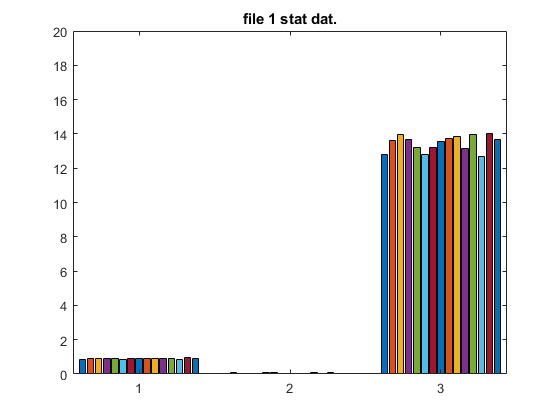

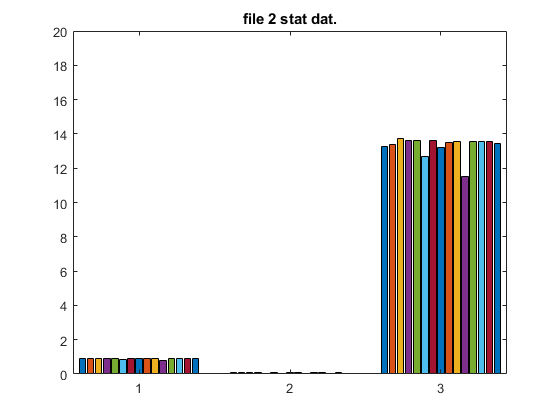

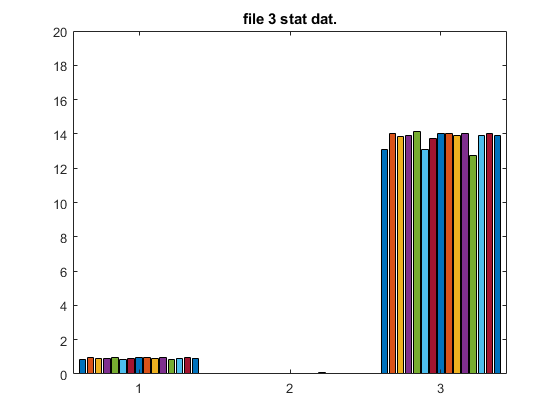

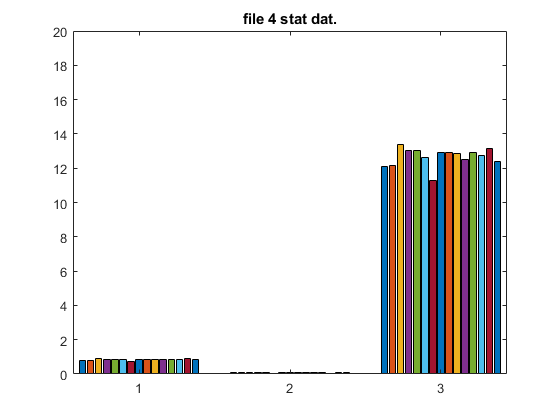

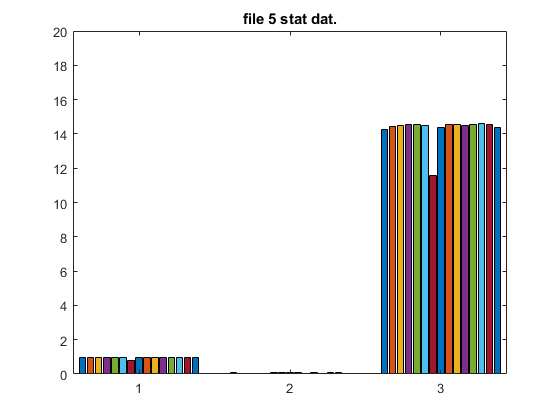

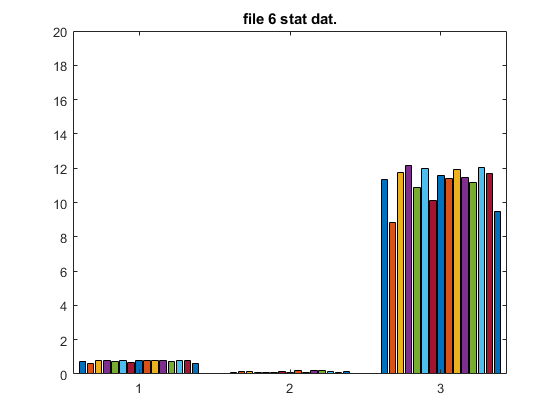

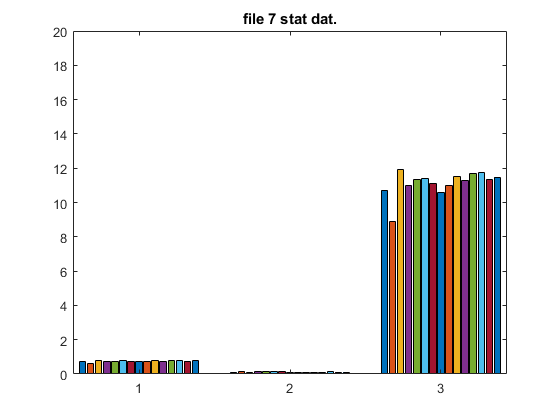

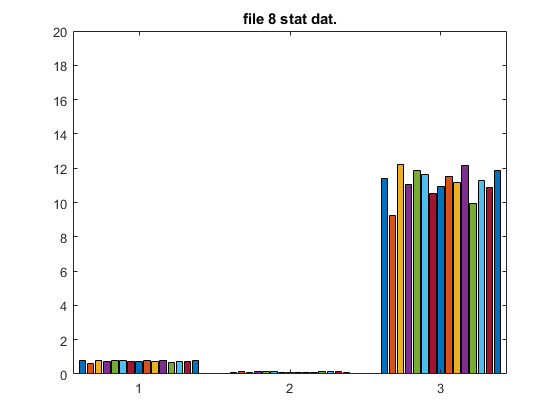

%plots fourier transform statistics fo each channel in each signal
for k = 1:numfiles
corrs = corr(tfftdat{k});
mCorrsF2D(1,:) = mean(corrs);
mCorrsF2D(2,:) = std(corrs);
mCorrsF2D(3,:) = sum(corrs);
figure

bar(mCorrsF2D);
ylim([0 20]);
title([ 'file '  num2str(k)  ' stat dat.'])
end

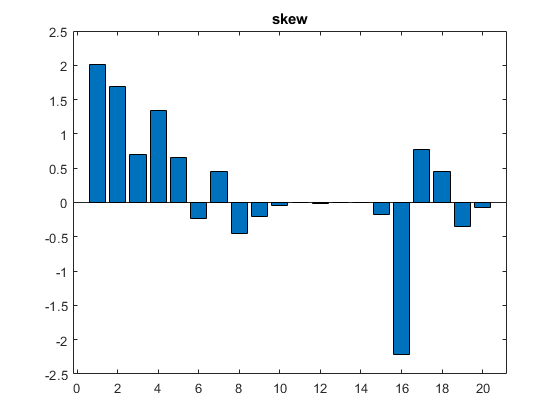

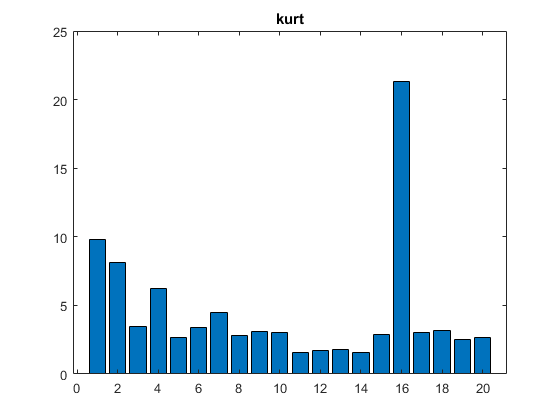

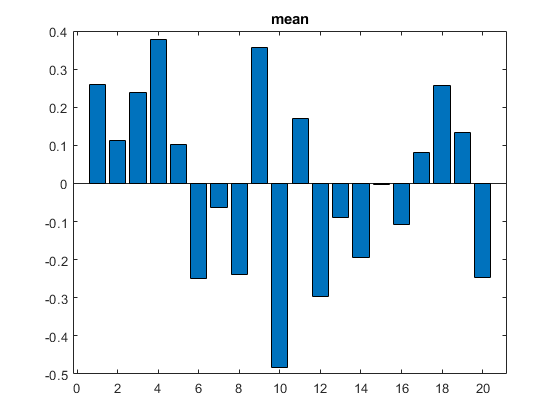

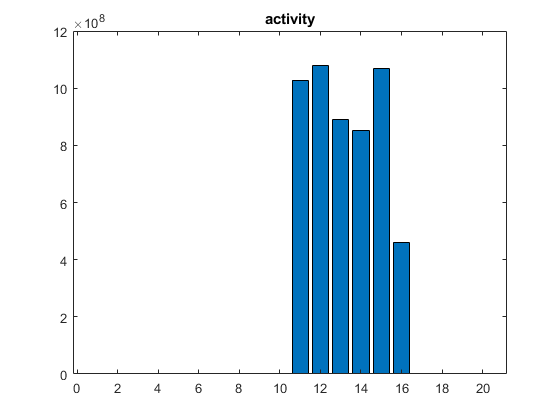

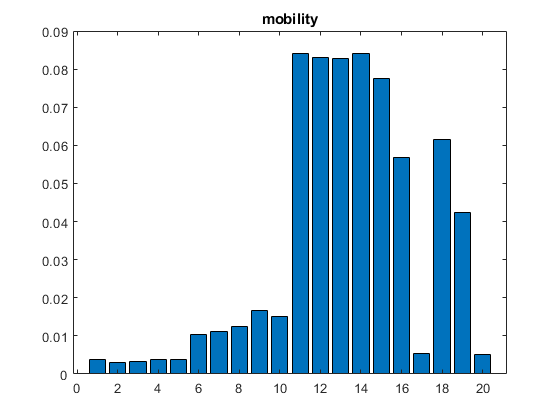

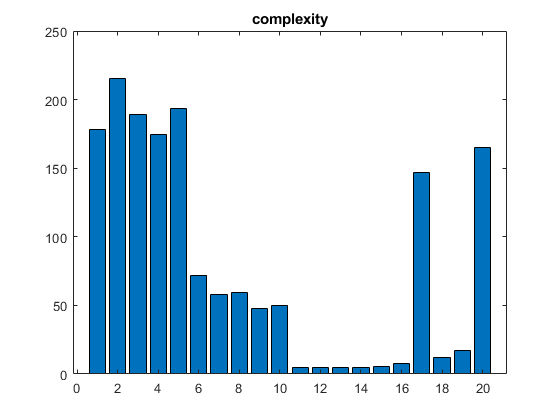

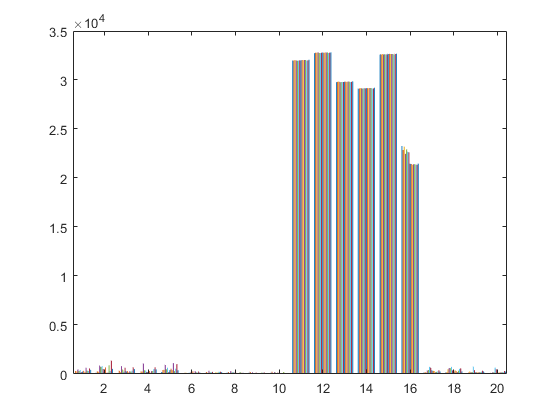

feat = 	1.0e+04 *

   -0.0000    5.6107    0.0000    0.0165    0.0003   -0.0000    5.6107    0.0000    0.0165    0.0003   -0.0000    5.6107    0.0000    0.0165    0.0003   -0.0000    5.6107    0.0000    0.0165    0.0003   -0.0000    5.6107    0.0000    0.0165    0.0003   -0.0000    5.6107    0.0000    0.0165    0.0003   -0.0000    5.6107    0.0000    0.0165    0.0003   -0.0000    5.6107    0.0000    0.0165    0.0003   -0.0000    5.6107    0.0000    0.0165    0.0003   -0.0000    5.6107    0.0000    0.0165    0.0003


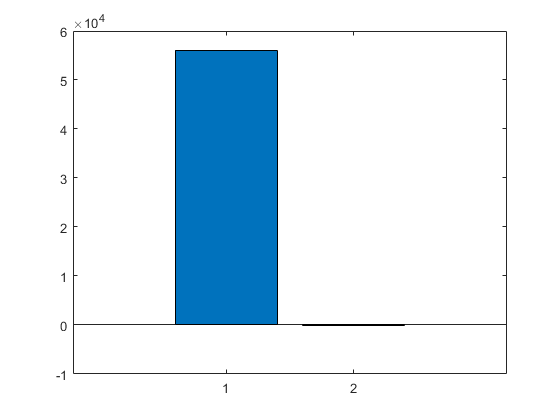


%plots statistics for channel 15 of each signal
statname = {'skew', 'kurt','mean','activity','mobility','complexity'};
for n = 1:6
    figure
    
    bar(stats(:,n))
    title(statname(n));
end

%shannon entropy

% plots standard deviation for each channel
figure
bar(stv);
